# Design by Emulation

# 2.1.1 Position PID-controller

## 2.1.1.1-2.1.1.2  Backward

run("load_params_estimatedValues.m");
% Open Simulink model
open_system('Simulink/DiscretePID.slx');

#### Simulation results [$$T_s = 1ms$$] 

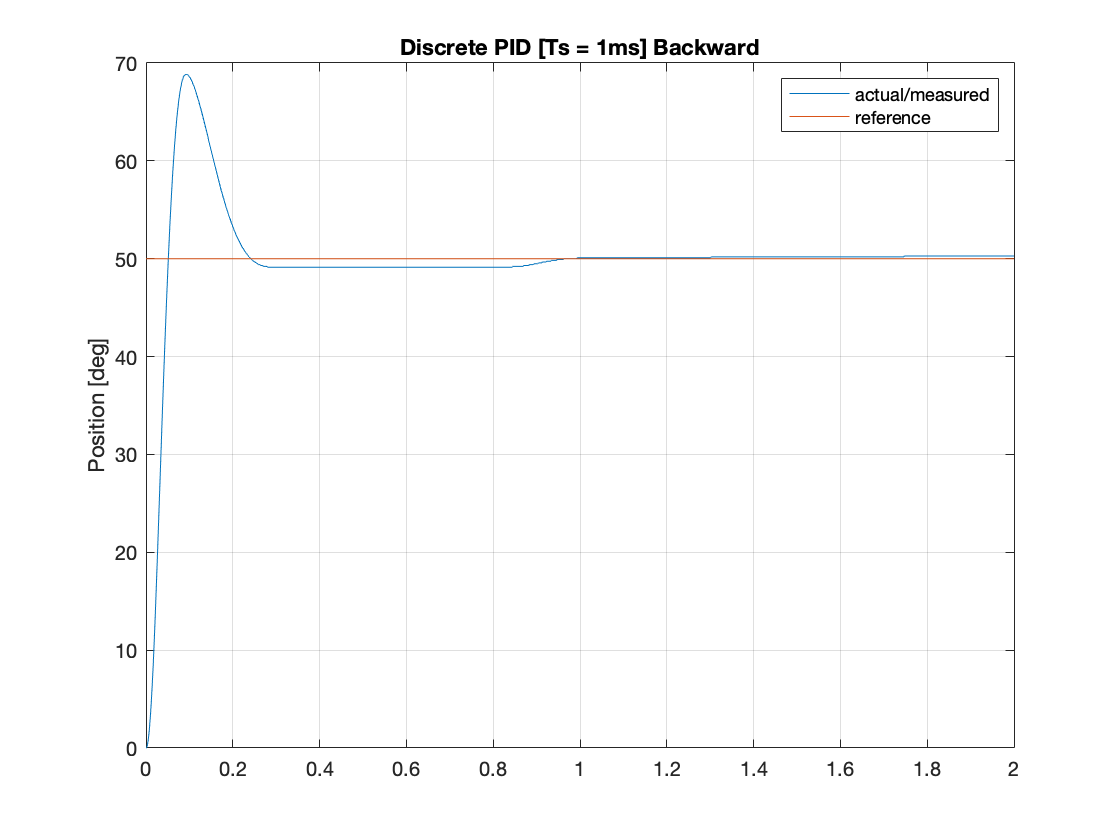

% Set parameters
set_param('DiscretePID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');
% Step
set_param('DiscretePID/switch','sw','1');
set_param('DiscretePID/Step','Time','0','Before','0','After','50');

% % PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0');
set_param('DiscretePID/Enable Feed-forward','Value','0');

% Sampling time
T_samp = 0.001;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/AW_gain','Gain','0');
set_param('DiscretePID/PID controller_AWFF1/AW_gain','Gain','0');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 1ms] Backward');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$]

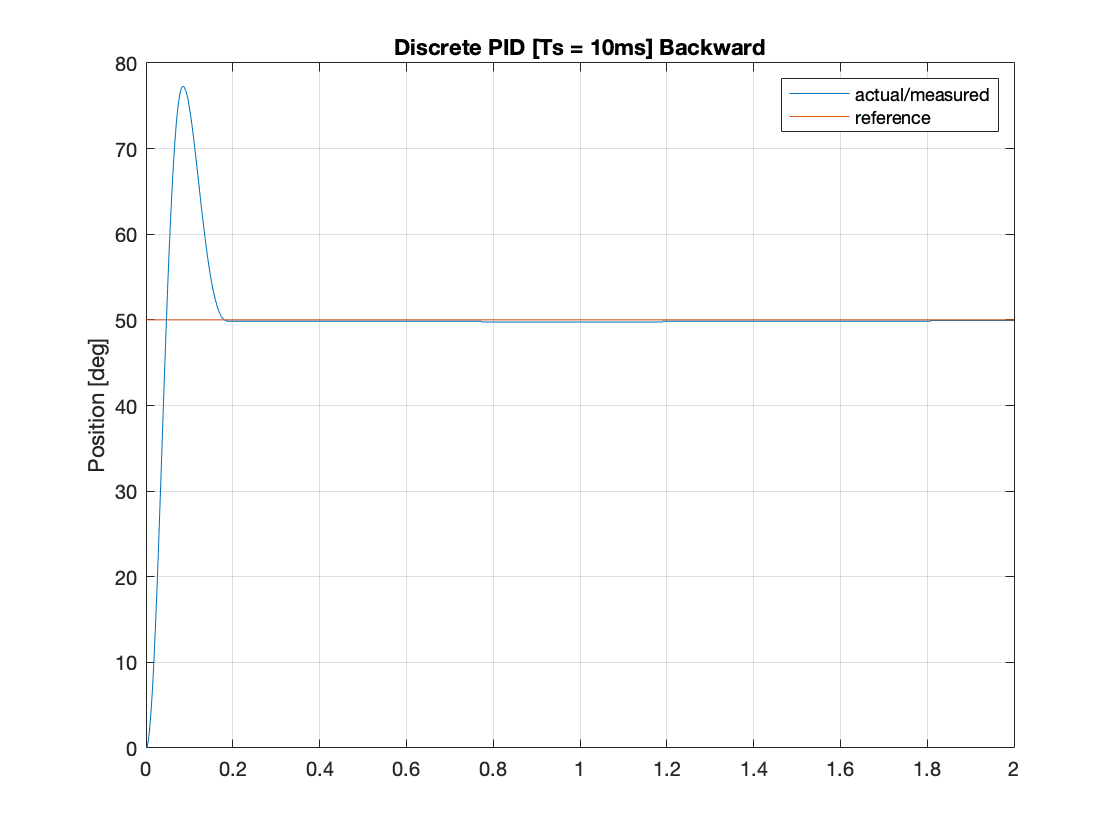

% Sampling time
T_samp = 0.01;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 10ms] Backward');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$]

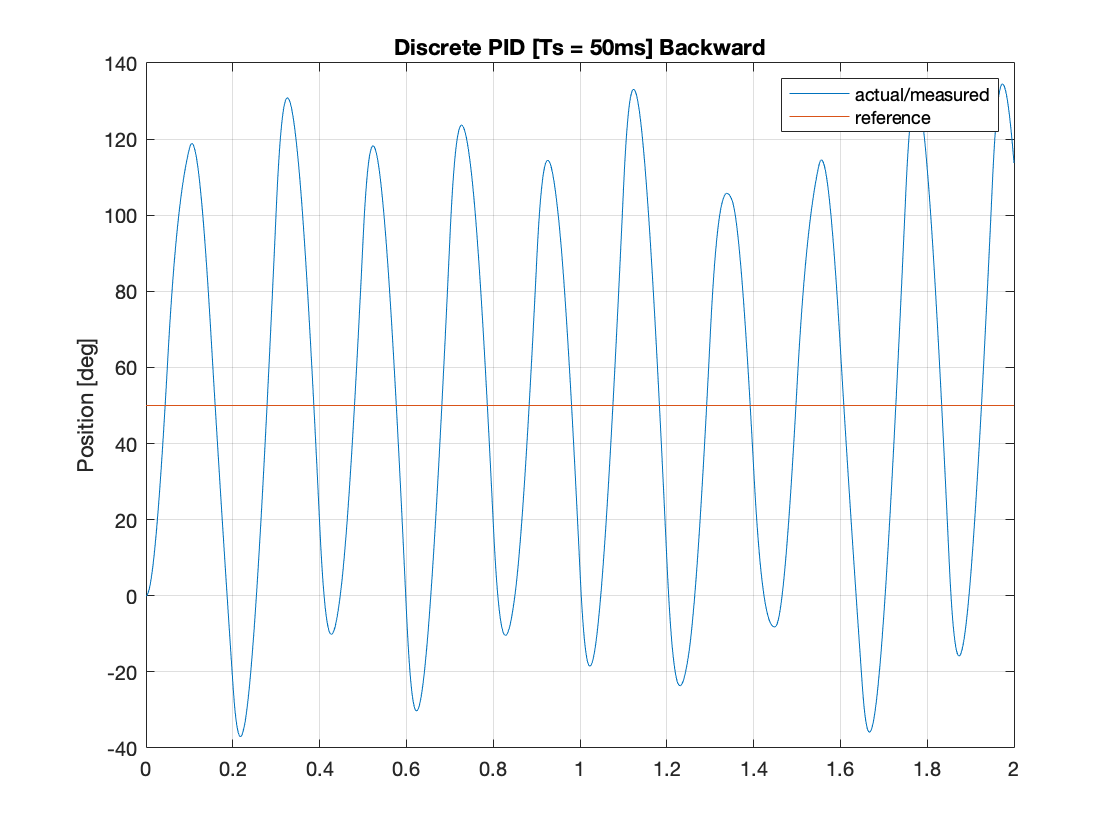

% Sampling time
T_samp = 0.05;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 50ms] Backward');
legend('actual/measured', 'reference');

## 2.1.1.3  Backward Anti-windup

#### Simulation results [$$T_s = 10ms$$] 

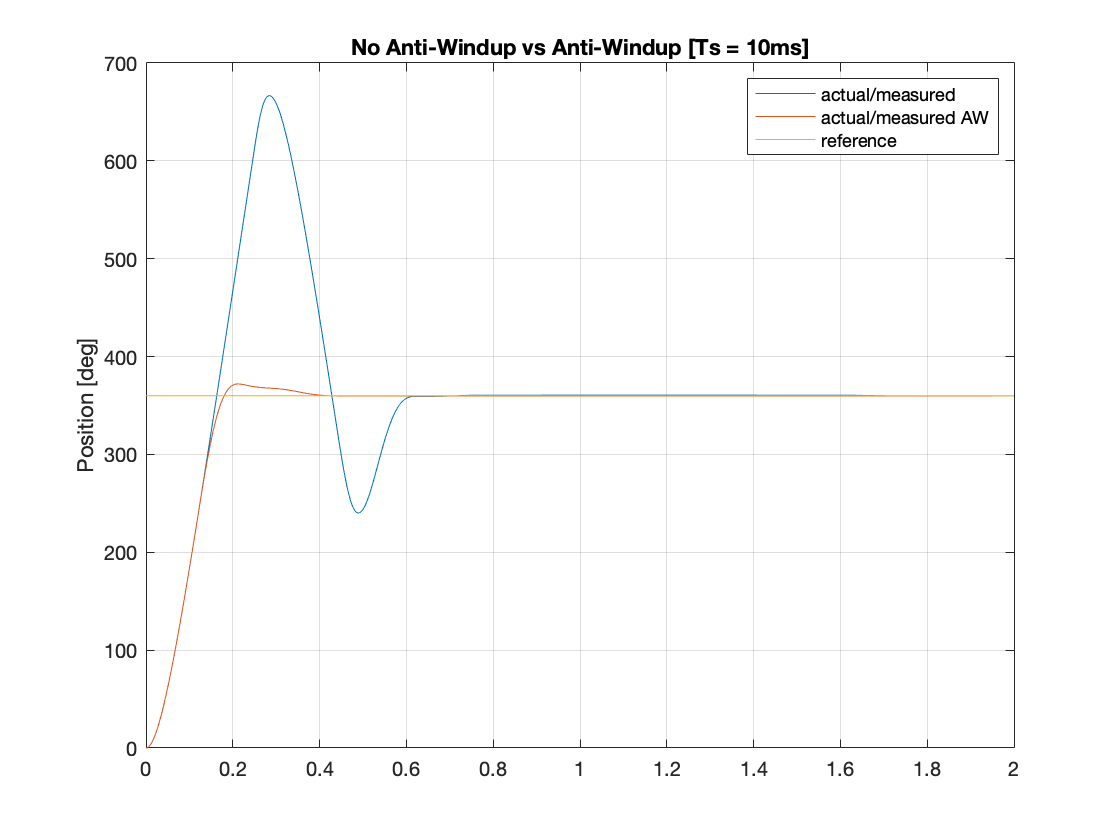

% Anti-Windup
AW.K_w = 5/0.15;

% Step
set_param('DiscretePID/switch','sw','1');
set_param('DiscretePID/switch1','sw','1');
set_param('DiscretePID/Step','Time','0','Before','0','After','360');
set_param('DiscretePID/Step1','Time','0','Before','0','After','360');

% PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0'); % Disable Anti-windup
set_param('DiscretePID/Enable Anti-Windup1','Value','1'); % Enable Anti-windup
set_param('DiscretePID/Enable Feed-forward','Value','0'); % Disable Feed-forward
set_param('DiscretePID/Enable Feed-forward1','Value','0'); % Disable Feed-forward

% Sampling time
T_samp = 0.01;

% Controller
back.der_num = [1 -1];
back.der_den = [pid.sim.T_l+T_samp -pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); 
set_param('DiscretePID/PID controller_AWFF1/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','back.der_num','Denominator','back.der_den','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF1/AW_gain','Gain','AW.K_w');

% Run simulation
sim('DiscretePID');

% Extract simulation results
AW.t = simres.time; % time vector 
AW.thl = simres.signals(1).values(:,1); % load position
AW.thl_AW = simres.signals(1).values(:,2); % load position AW
AW.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure
plot(AW.t, AW.thl);
hold on;
plot(AW.t, AW.thl_AW);
hold on;
plot(AW.t, AW.thl_Ref);
ylabel('Position [deg]');
grid on;
title('No Anti-Windup vs Anti-Windup [Ts = 10ms]');
legend('actual/measured', 'actual/measured AW', 'reference');

## 2.1.1.4  Backward Feed-forward [OPTIONAL]

#### Simulation results [$$T_s = 10ms$$] 

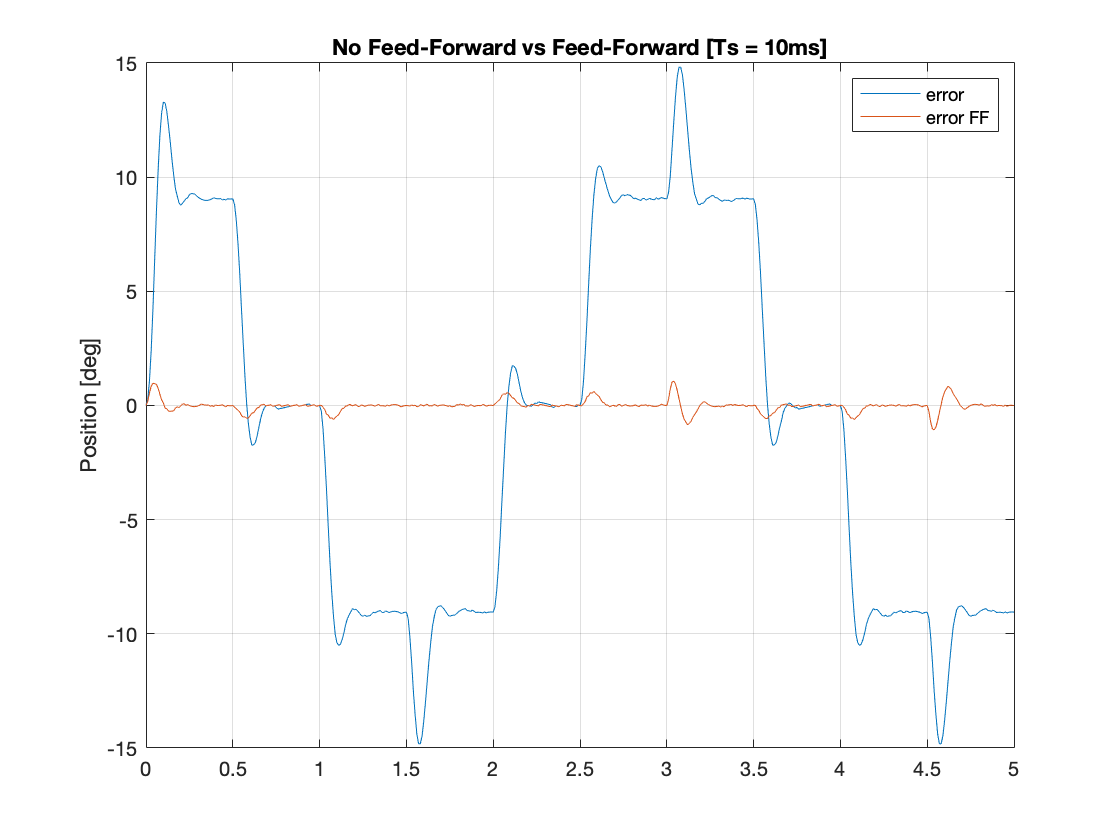

% Set parameters
set_param('DiscretePID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '5');

% Sequence generator
set_param('DiscretePID/switch','sw','0');
set_param('DiscretePID/switch1','sw','0');

% % PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0'); % Disable Anti-windup
set_param('DiscretePID/Enable Anti-Windup1','Value','0'); % Disable Anti-windup
set_param('DiscretePID/Enable Feed-forward','Value','0'); % Disable Feed-forward
set_param('DiscretePID/Enable Feed-forward1','Value','1'); % Enable Feed-forward

% Sampling time
T_samp = 0.01;

% Run simulation
sim('DiscretePID');

% Extract simulation results
FF.t = simerr.time; % time vector 
FF.err = simerr.signals(1).values(:,1); % load position
FF.err_FF = simerr.signals(1).values(:,2); % load position AW

% Plot simulation results
figure
plot(FF.t, FF.err);
hold on;
plot(FF.t, FF.err_FF);
ylabel('Position [deg]');
grid on;
title('No Feed-Forward vs Feed-Forward [Ts = 10ms]');
legend('error', 'error FF');

## 2.1.1.5  Forward

#### Simulation results [$$T_s = 1ms$$] 

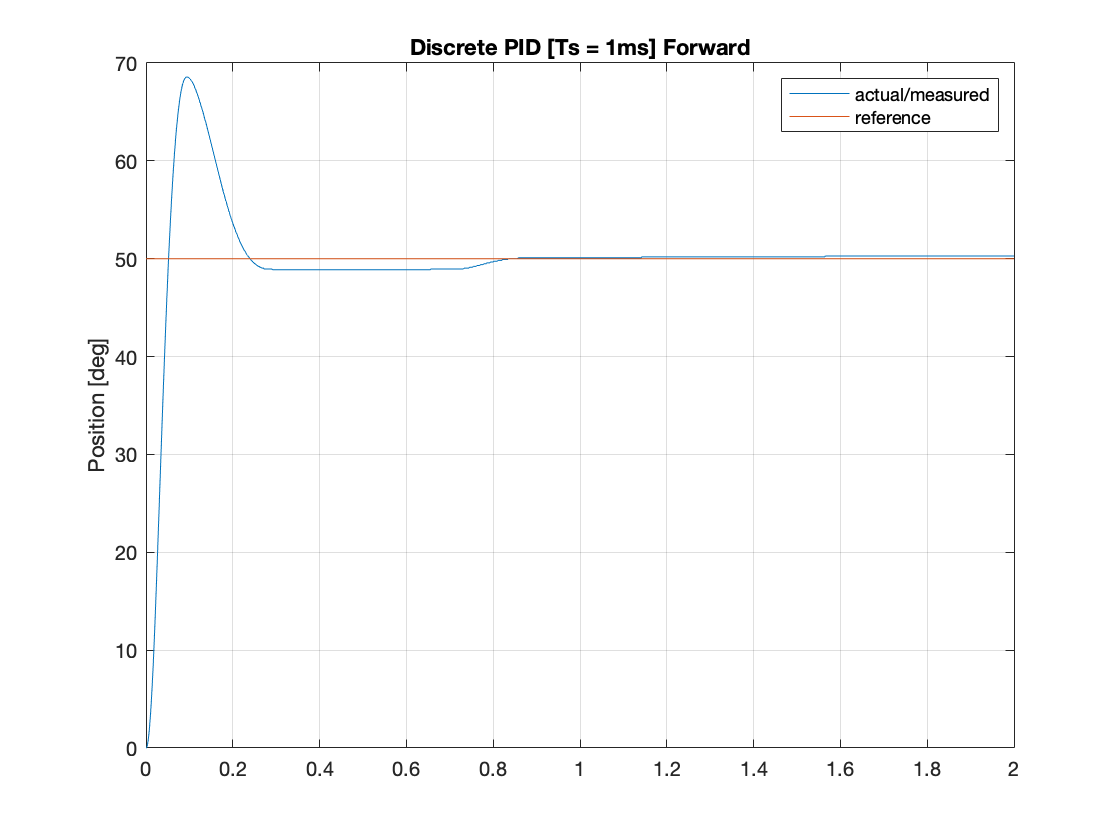

% Set parameters
set_param('DiscretePID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2');
% Step
set_param('DiscretePID/switch','sw','1');
set_param('DiscretePID/Step','Time','0','Before','0','After','50');

% % PID controller AW & FF
set_param('DiscretePID/Enable Anti-Windup','Value','0');
set_param('DiscretePID/Enable Feed-forward','Value','0');

% Sampling time
T_samp = 0.001;

% Controller
forw.der_num = [1 -1];
forw.der_den = [pid.sim.T_l T_samp-pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','forw.der_num','Denominator','forw.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 1ms] Forward');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$] 

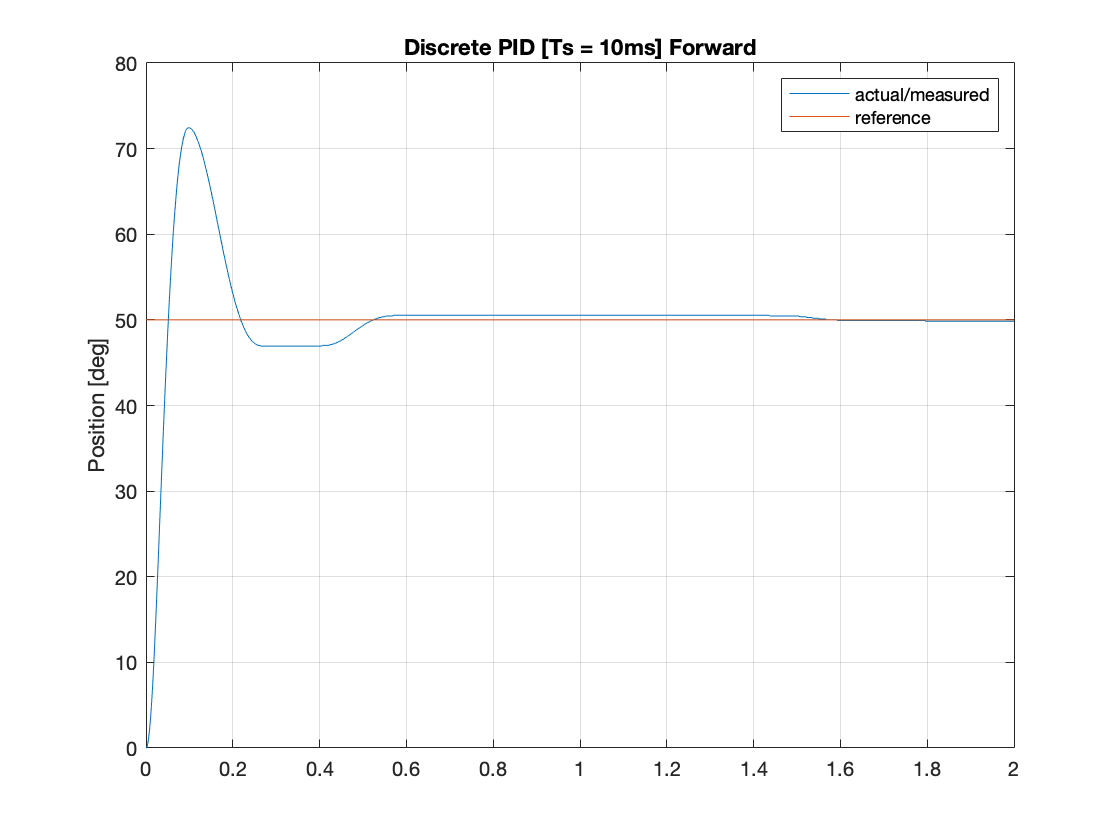

% Sampling time
T_samp = 0.01;

% Controller
forw.der_num = [1 -1];
forw.der_den = [pid.sim.T_l T_samp-pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','forw.der_num','Denominator','forw.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 10ms] Forward');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$]

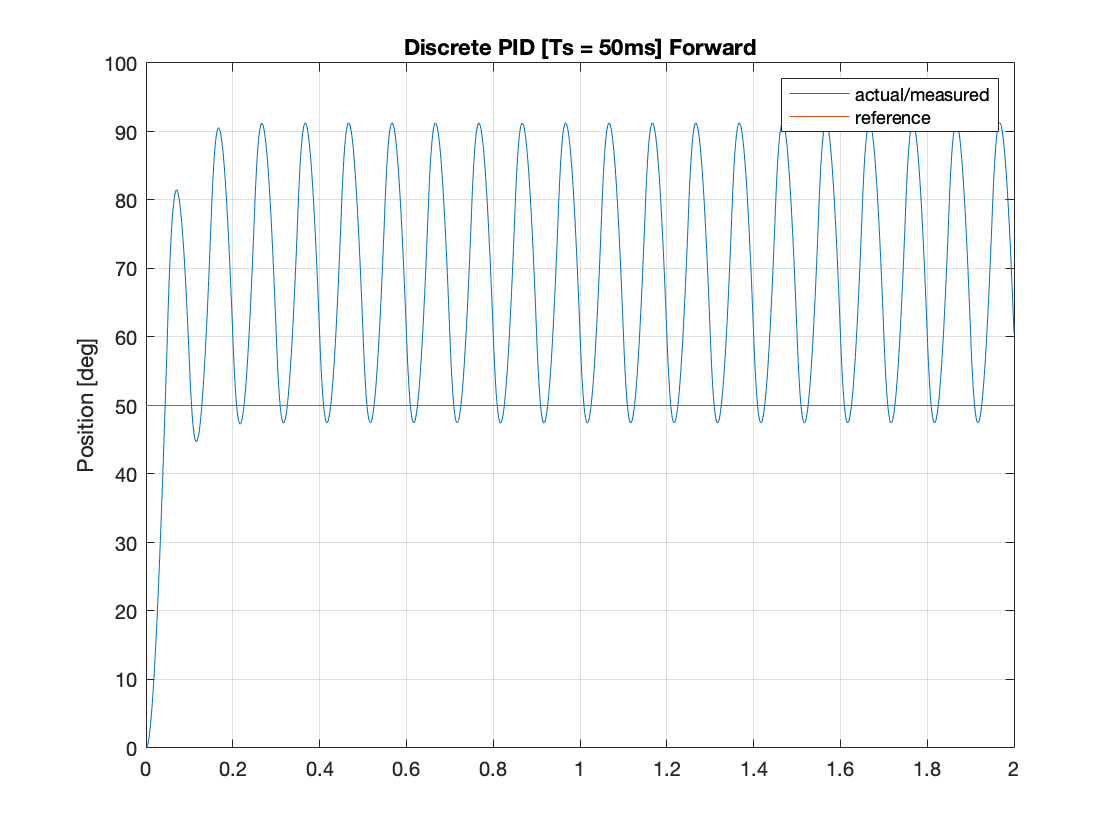

% Sampling time
T_samp = 0.05;

% Controller
forw.der_num = [1 -1];
forw.der_den = [pid.sim.T_l T_samp-pid.sim.T_l];
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','forw.der_num','Denominator','forw.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 50ms] Forward');
legend('actual/measured', 'reference');

## 2.1.1.5  Tustin

#### Simulation results [$$T_s = 1ms$$]

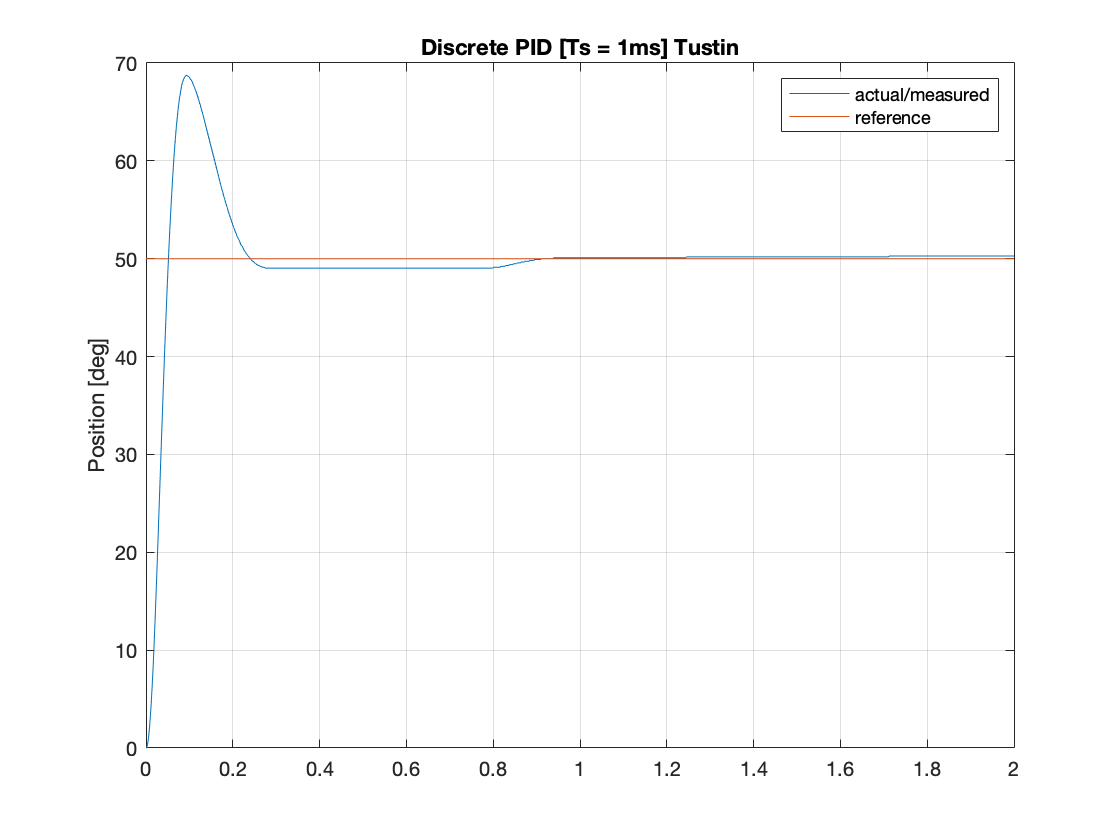

% Sampling time
T_samp = 0.001;

% Controller
tust.der_num = [2 -2];
tust.der_den = [2*pid.sim.T_l+T_samp T_samp-2*pid.sim.T_l]; 
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Trapezoidal','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','tust.der_num','Denominator','tust.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 1ms] Tustin');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$]

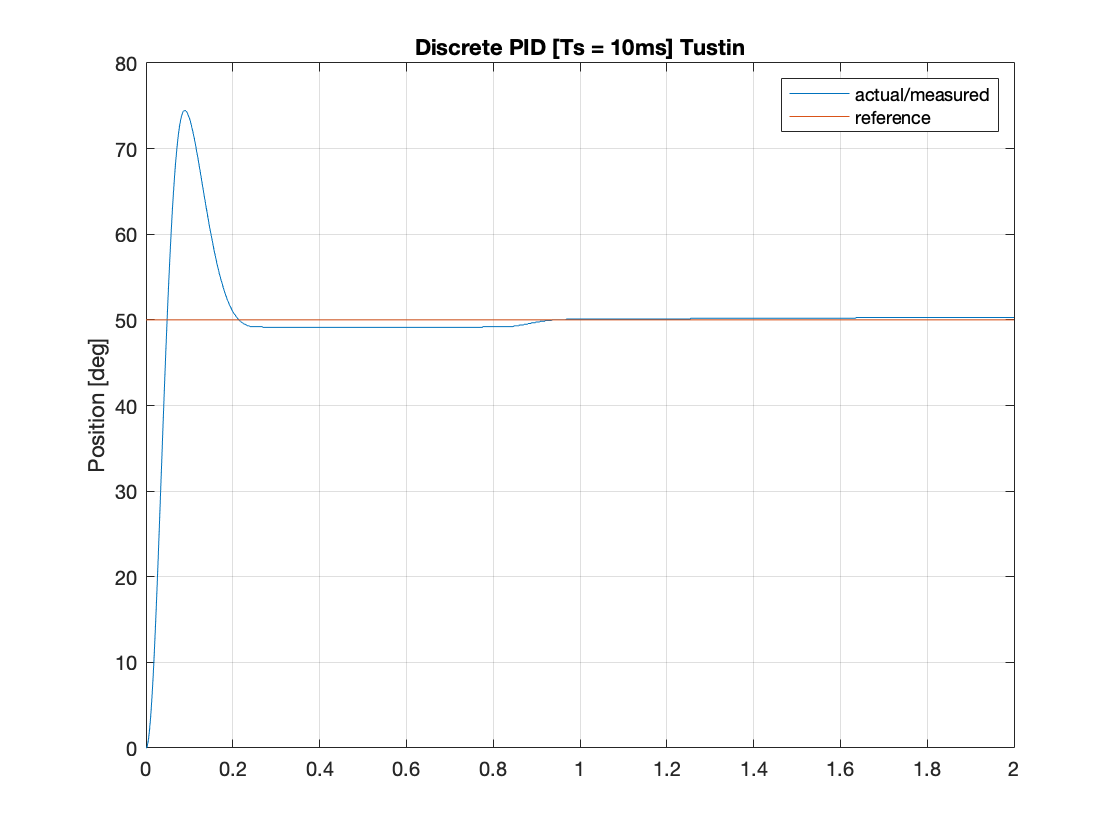

% Sampling time
T_samp = 0.01;

% Controller
tust.der_num = [2 -2];
tust.der_den = [2*pid.sim.T_l+T_samp T_samp-2*pid.sim.T_l]; 
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Trapezoidal','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','tust.der_num','Denominator','tust.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 10ms] Tustin');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$]

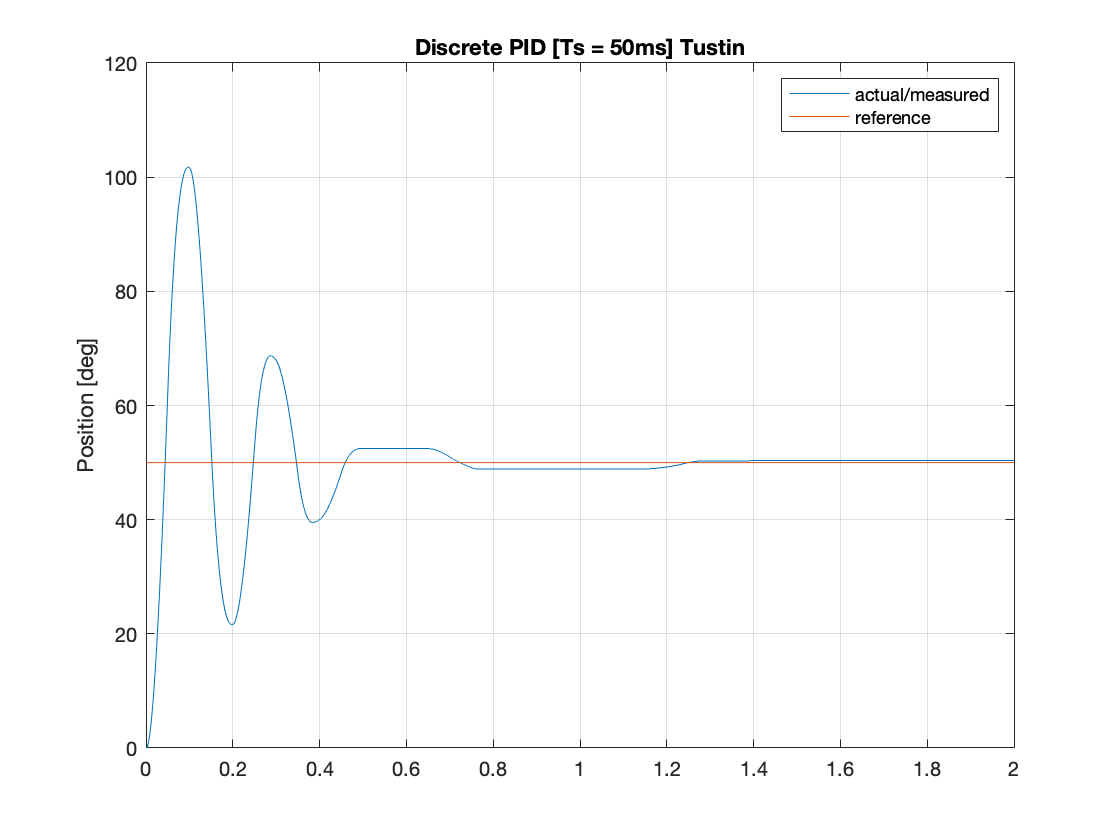

% Sampling time
T_samp = 0.05;

% Controller
tust.der_num = [2 -2];
tust.der_den = [2*pid.sim.T_l+T_samp T_samp-2*pid.sim.T_l]; 
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Integrator','IntegratorMethod','Integration: Trapezoidal','SampleTime','T_samp');
set_param('DiscretePID/PID controller_AWFF/Discrete-Time Real Derivator','Numerator','tust.der_num','Denominator','tust.der_den','SampleTime','T_samp');

% Run simulation
sim('DiscretePID');

% Extract simulation results
pid.t = simres1.time; % time vector 
pid.thl = simres1.signals(1).values(:,1); % load position
pid.thl_Ref = simres1.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(pid.t, pid.thl);
hold on;
plot(pid.t, pid.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 50ms] Tustin');
legend('actual/measured', 'reference');

## 2.1.1.5  ZOH

#### Simulation results [$$T_s = 1ms$$] 

% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Sampling time
T_samp = 0.001;

[zoh_num,zoh_den] = tfdata(c2d(Cs,T_samp,'zoh'));
zoh_num = cell2mat(zoh_num);
zoh_den = cell2mat(zoh_den);

% Open Simulink model
open_system('Simulink/Pid_ZOH.slx');

% Set parameters
set_param('Pid_ZOH', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2');
% Step
set_param('Pid_ZOH/Step','Time','0','Before','0','After','50');

% Controller
set_param('Pid_ZOH/Controller/Discrete Transfer Fcn','Numerator','zoh_num','Denominator','zoh_den');

% Run simulation
sim('Pid_ZOH');

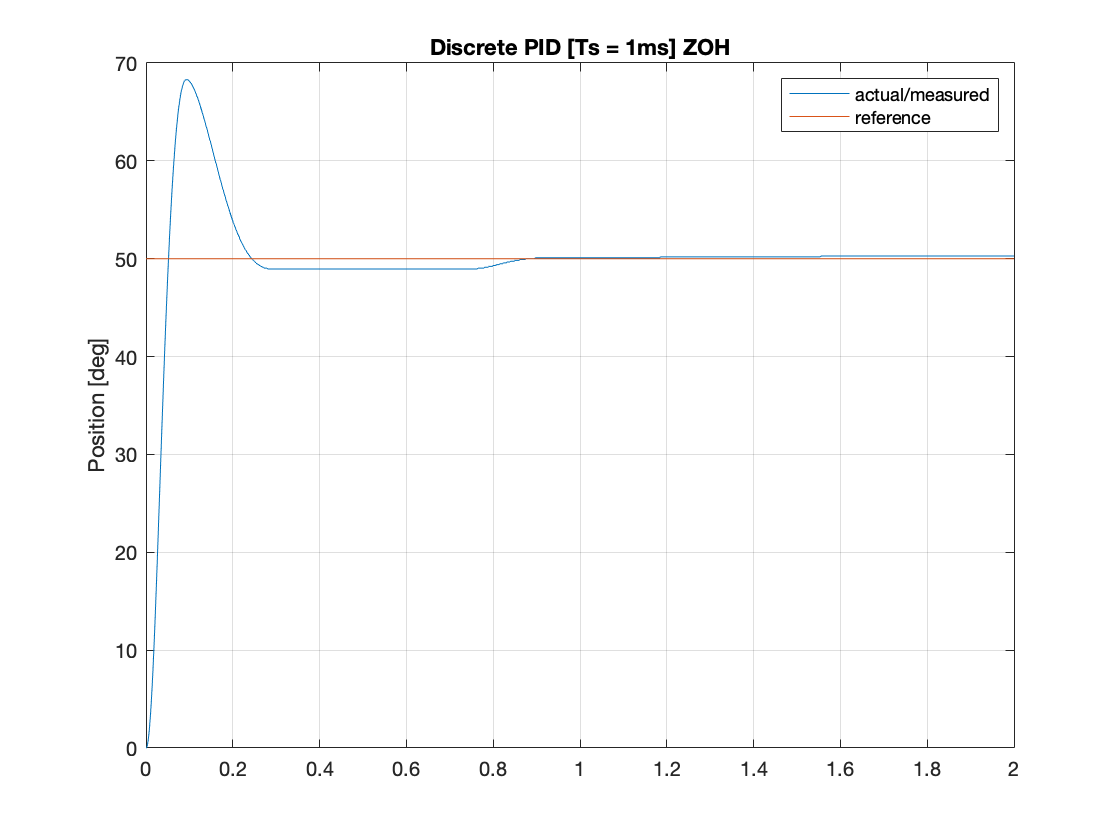


% Extract simulation results
zoh.t = simres.time; % time vector 
zoh.thl = simres.signals(1).values(:,1); % load position
zoh.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(zoh.t, zoh.thl);
hold on;
plot(zoh.t, zoh.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 1ms] ZOH');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$] 

% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Sampling time
T_samp = 0.01;

[zoh_num,zoh_den] = tfdata(c2d(Cs,T_samp,'zoh'));
zoh_num = cell2mat(zoh_num);
zoh_den = cell2mat(zoh_den);

% Controller
set_param('Pid_ZOH/Controller/Discrete Transfer Fcn','Numerator','zoh_num','Denominator','zoh_den');

% Run simulation
sim('Pid_ZOH');

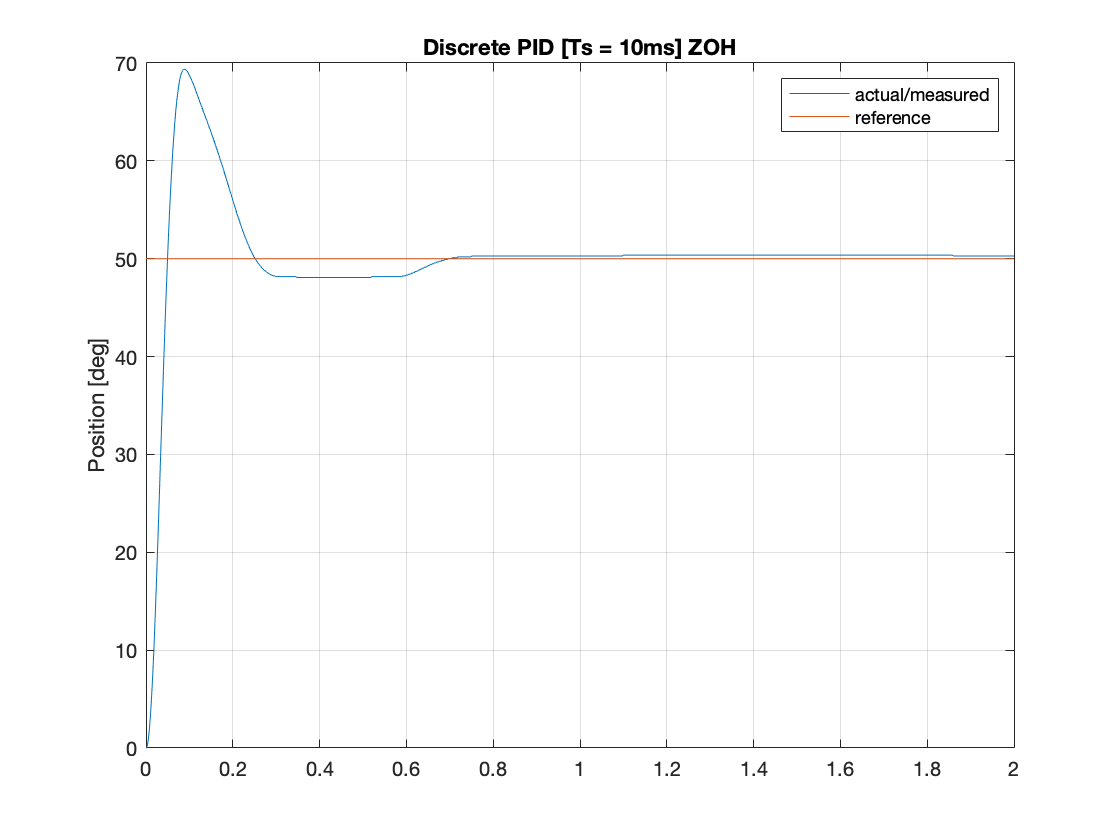


% Extract simulation results
zoh.t = simres.time; % time vector 
zoh.thl = simres.signals(1).values(:,1); % load position
zoh.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(zoh.t, zoh.thl);
hold on;
plot(zoh.t, zoh.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 10ms] ZOH');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$] 

% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Sampling time
T_samp = 0.05;

[zoh_num,zoh_den] = tfdata(c2d(Cs,T_samp,'zoh'));
zoh_num = cell2mat(zoh_num);
zoh_den = cell2mat(zoh_den);

% Controller
set_param('Pid_ZOH/Controller/Discrete Transfer Fcn','Numerator','zoh_num','Denominator','zoh_den');

% Run simulation
sim('Pid_ZOH');

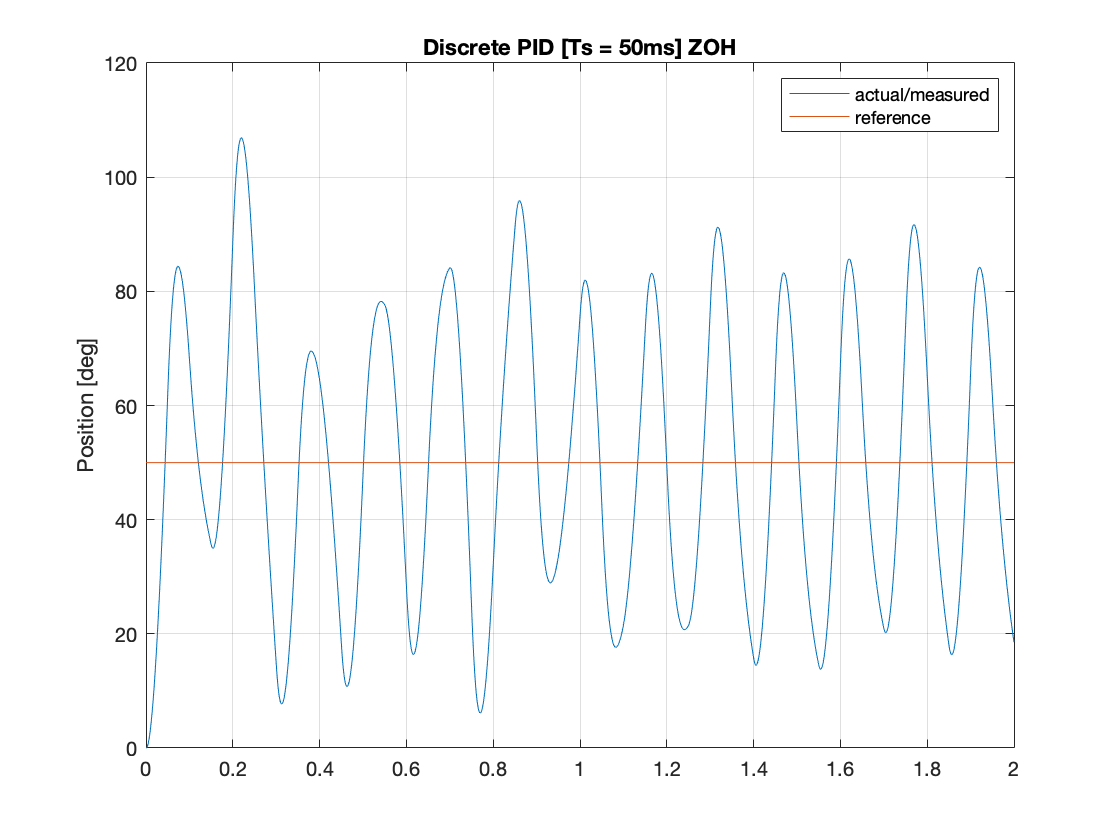


% Extract simulation results
zoh.t = simres.time; % time vector 
zoh.thl = simres.signals(1).values(:,1); % load position
zoh.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(zoh.t, zoh.thl);
hold on;
plot(zoh.t, zoh.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete PID [Ts = 50ms] ZOH');
legend('actual/measured', 'reference');

# 2.1.2 Position state–space controller

## Reduced-Order Observer [Continuos-case]

## 2.1.2.1-2.1.2.2 NOMINAL

% State-Space model
state_space.T_m = (simp_model.Req*est_par.J_eq)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.K_m = (drv.dcgain*mot.Kt)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.A = [0 1;0 -1/state_space.T_m];
state_space.B = [0;state_space.K_m/(state_space.T_m*gbox.N)];
state_space.C = [1 0];
state_space.D = 0;

% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);

% Compute L
reduced.L = place(-1/state_space.T_m,1,5*min(eig(Cs)));

% A0
reduced.A0 = -1/state_space.T_m - reduced.L;
% B0
reduced.B0 = [state_space.K_m/(gbox.N*state_space.T_m) (-1/state_space.T_m - reduced.L)*reduced.L];
% C0
reduced.C0 = [0;1];
% D0
reduced.D0 = [0 1;0 reduced.L];

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
nominal.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
nominal.wn = 3/(nominal.delta*ts);

% Nominal control
nominal.X = linsolve([state_space.A,state_space.B;state_space.C 0],[0;0;1]);
nominal.N_x = nominal.X(1:2,:);
nominal.N_u = nominal.X(3,:);

% Pole placement
nominal.p1 = -nominal.delta*nominal.wn + 1i*nominal.wn*sqrt(1-nominal.delta^2);
nominal.p2 = conj(nominal.p1);
nominal.poles = [nominal.p1 nominal.p2];
nominal.K = place(state_space.A,state_space.B,nominal.poles);

% Open Simulink model
open_system('Simulink/Cont_ReducedOrder.slx');

#### Simulation results [$$40°$$] 

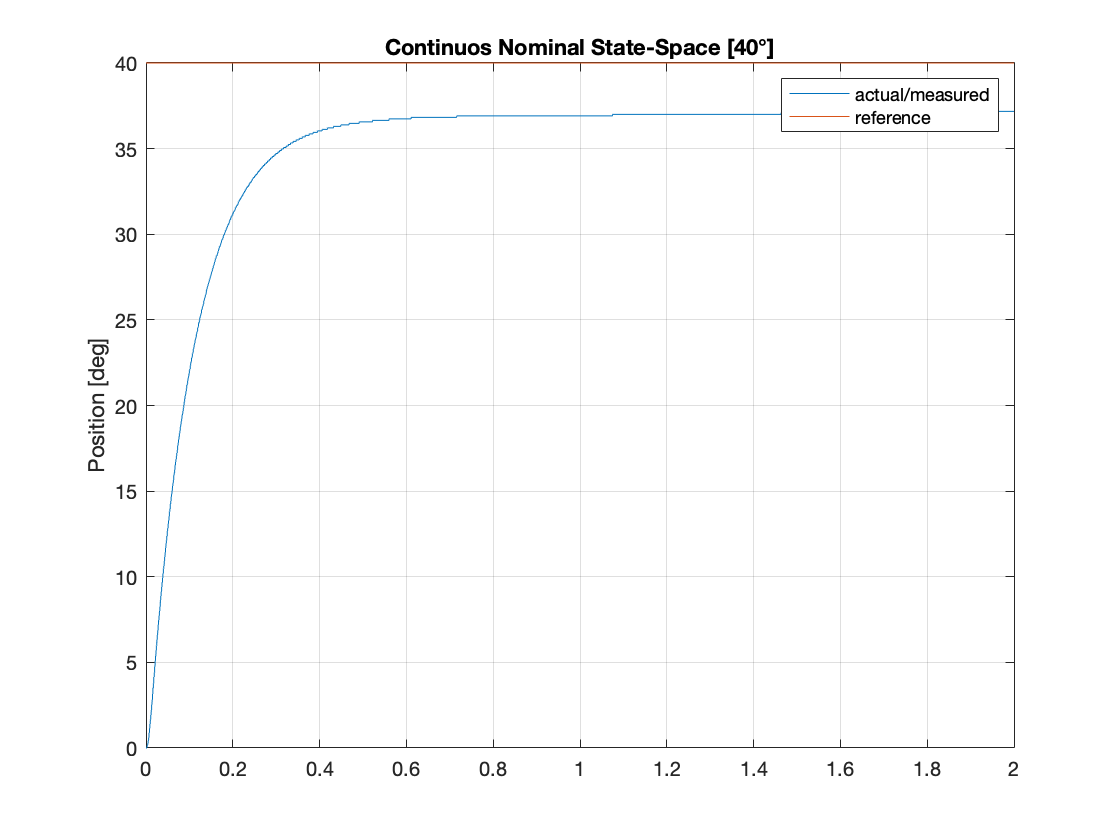

% Set parameters
set_param('Cont_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2');
% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','40');

% Controller
set_param('Cont_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Cont_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Cont_ReducedOrder/Controller/State feedback gain','Gain','nominal.K','Multiplication','Matrix(K*u)');
set_param('Cont_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Cont_ReducedOrder/Controller/Ki','Gain','0'); % Ki

% Continuos Reduced state observer
set_param('Cont_ReducedOrder/Reduced Order Observer','A','reduced.A0','B','reduced.B0','C','reduced.C0','D','reduced.D0');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Continuos Nominal State-Space [40°]');
legend('actual/measured', 'reference');

#### Simulation results [$$70°$$] 

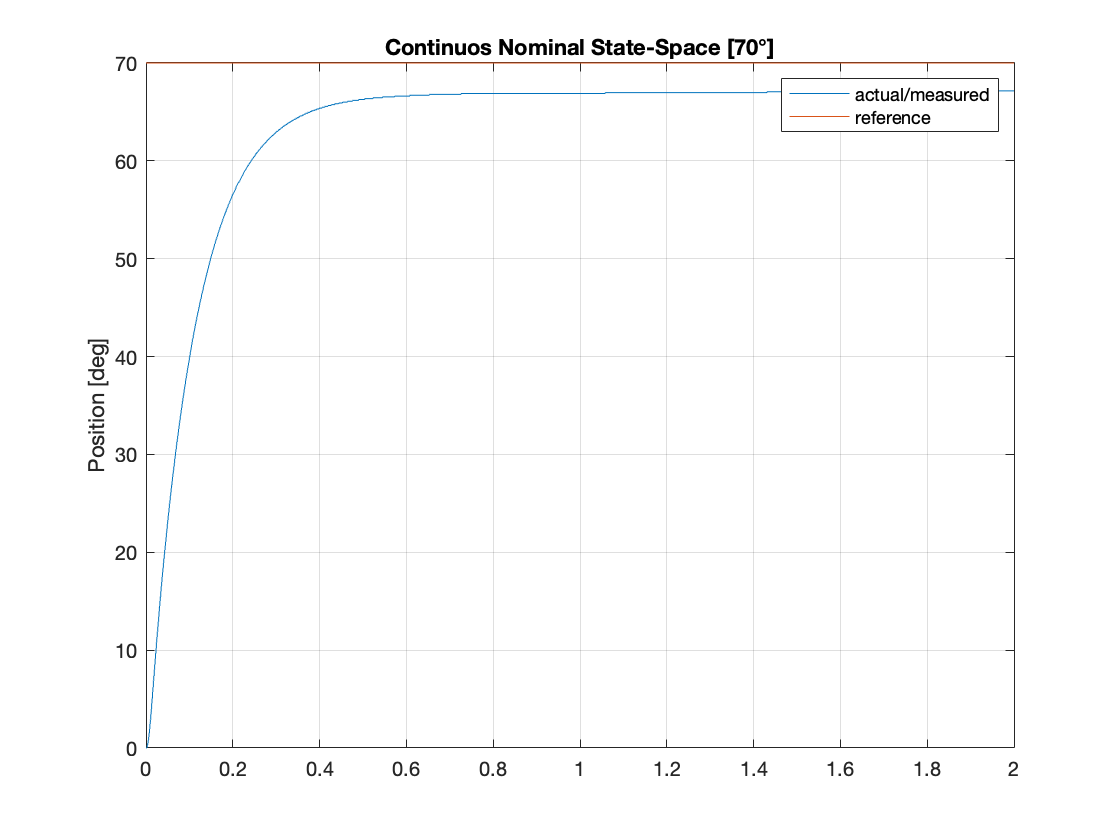

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','70');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Continuos Nominal State-Space [70°]');
legend('actual/measured', 'reference');

#### Simulation results [$$120°$$] 

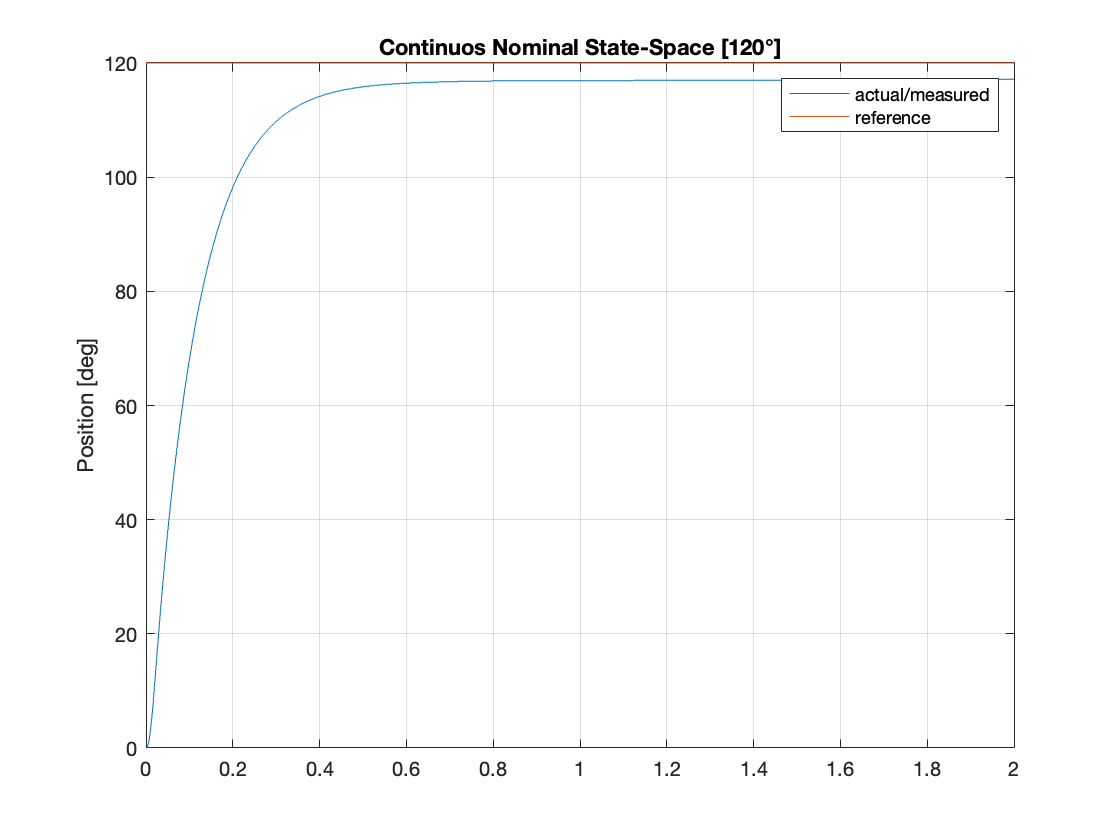

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','120');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Continuos Nominal State-Space [120°]');
legend('actual/measured', 'reference');

## Reduced-Order Observer [Discrete-case: Forward]

## 2.1.2.3-2.1.2.4 NOMINAL

#### Simulation results [$$T_s = 1ms$$] 

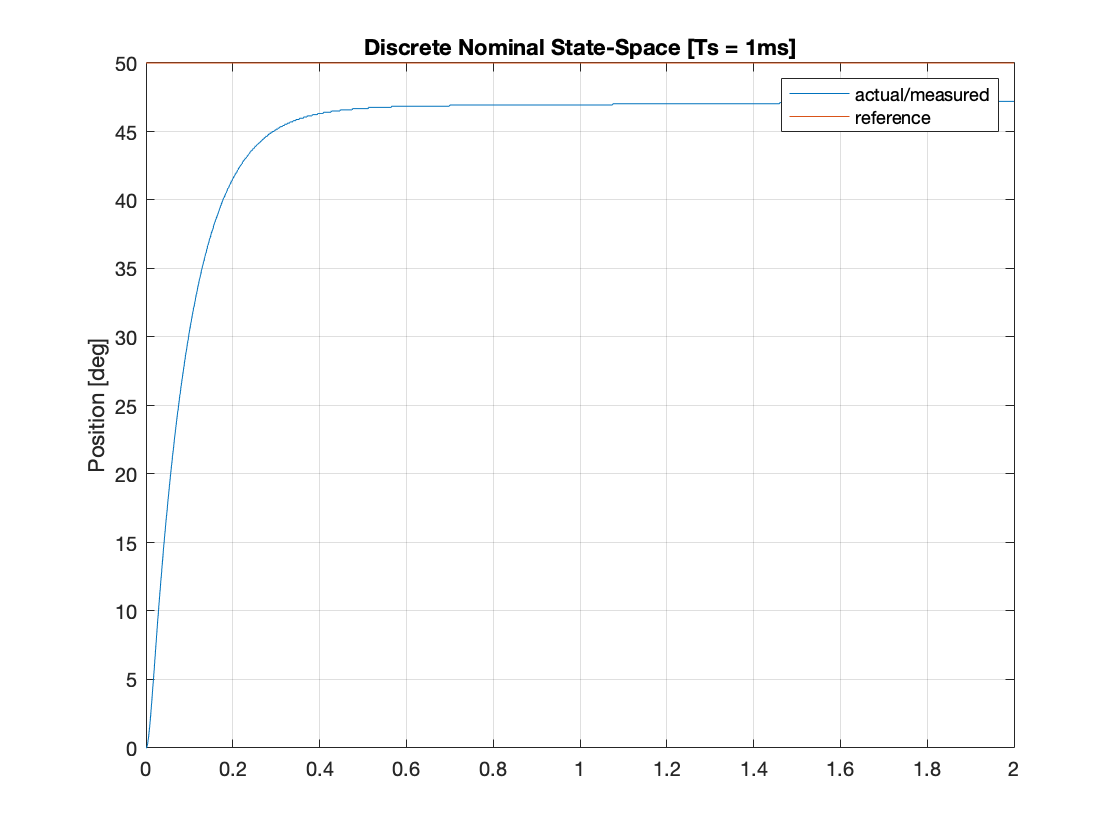

% Sampling time
T_samp = 0.001;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Open Simulink model
open_system('Simulink/Disc_ReducedOrder.slx');
% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');
% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','nominal.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_3_1ms.t = simres.time; % time vector 
reduced_3_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_3_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_3_1ms.t, reduced_3_1ms.thl);
hold on;
plot(reduced_3_1ms.t, reduced_3_1ms.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 1ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$] 

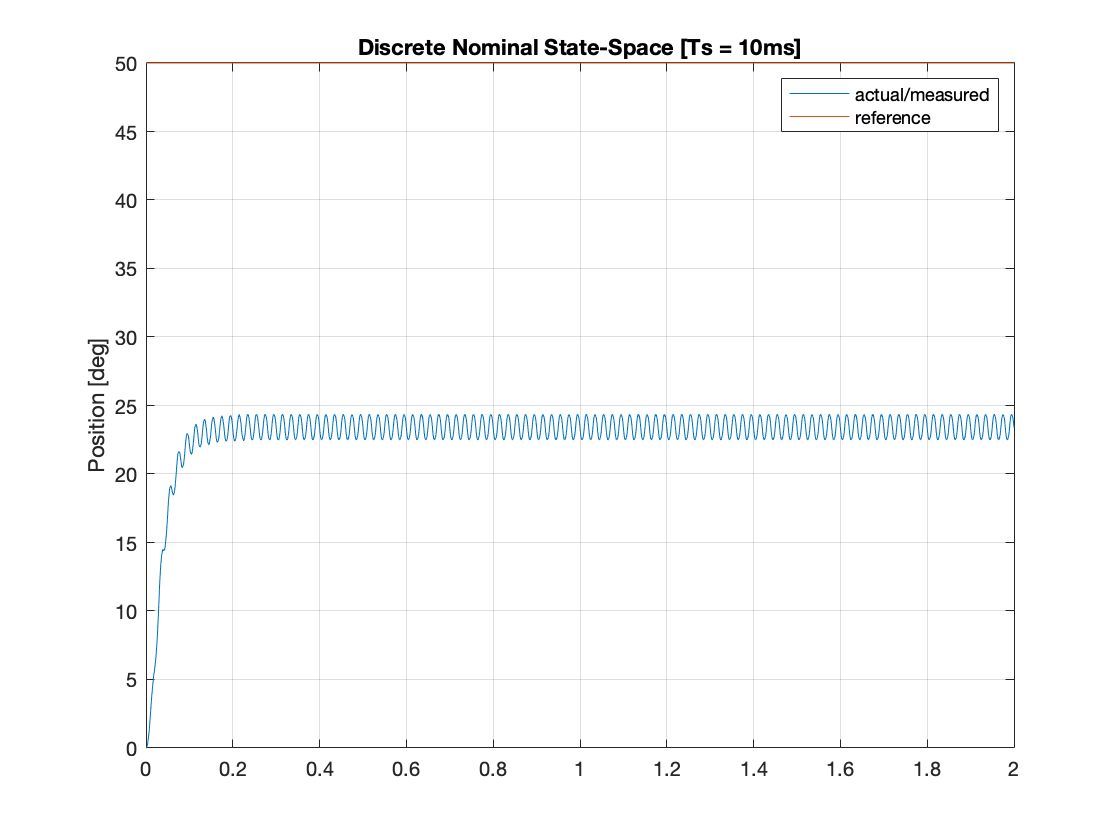

% Sampling time
T_samp = 0.01;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_3_10ms.t = simres.time; % time vector 
reduced_3_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_3_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_3_10ms.t, reduced_3_10ms.thl);
hold on;
plot(reduced_3_10ms.t, reduced_3_10ms.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 10ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$] 

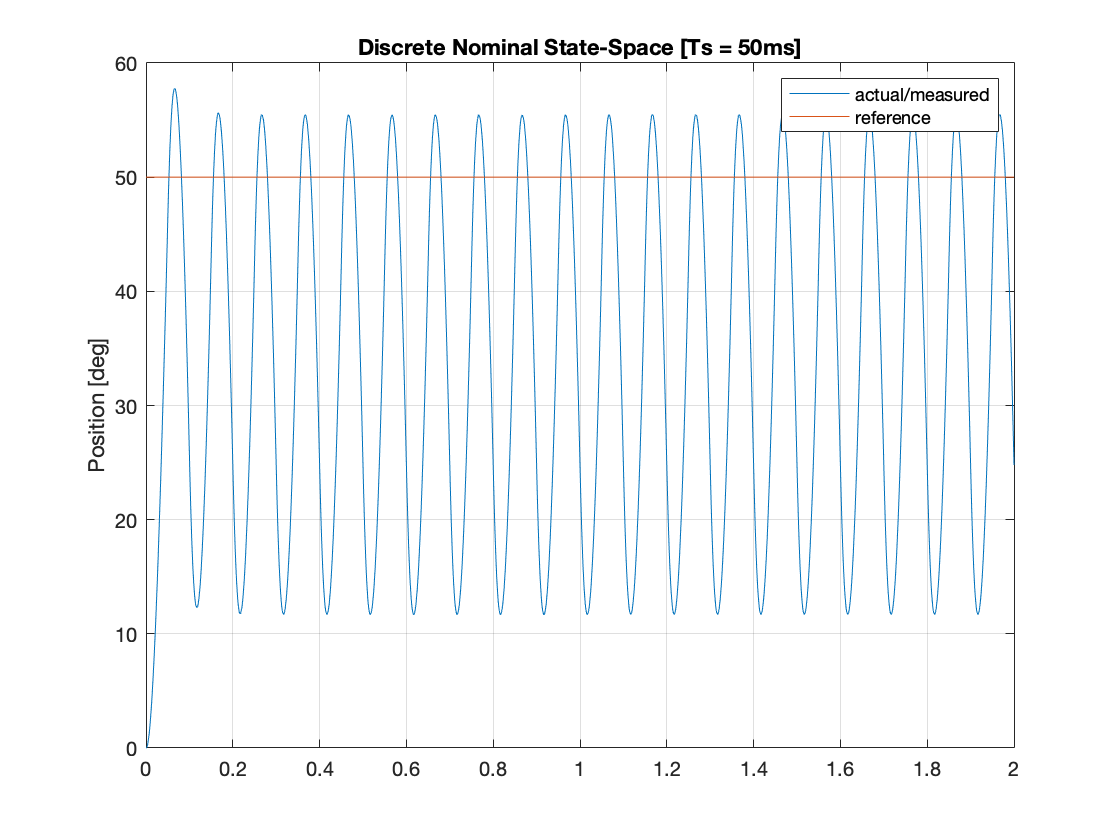

% Sampling time
T_samp = 0.05;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_3_50ms.t = simres.time; % time vector 
reduced_3_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_3_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_3_50ms.t, reduced_3_50ms.thl);
hold on;
plot(reduced_3_50ms.t, reduced_3_50ms.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 50ms]');
legend('actual/measured', 'reference');

## Reduced-Order Observer [Continuos-case]

## 2.1.2.5 INTEGRAL

% Augmented state-space
robust.Ae = [0 state_space.C;[0;0] state_space.A];
robust.Be = [0;state_space.B];
robust.Ce = [0 state_space.C];

% Real and imaginary parts of the eigenvalues
robust.sigma = -nominal.delta*nominal.wn;
robust.wd = nominal.wn*sqrt(1-nominal.delta^2);

% Pole placement
robust.poles = [2*robust.sigma + 1i*robust.wd, 2*robust.sigma - 1i*robust.wd, 2*robust.sigma];

% Ke
robust.Ke = place(robust.Ae,robust.Be,robust.poles);
robust.Ki = robust.Ke(1);
robust.K = robust.Ke(1,2:3);


#### Simulation results [$$40°$$] 

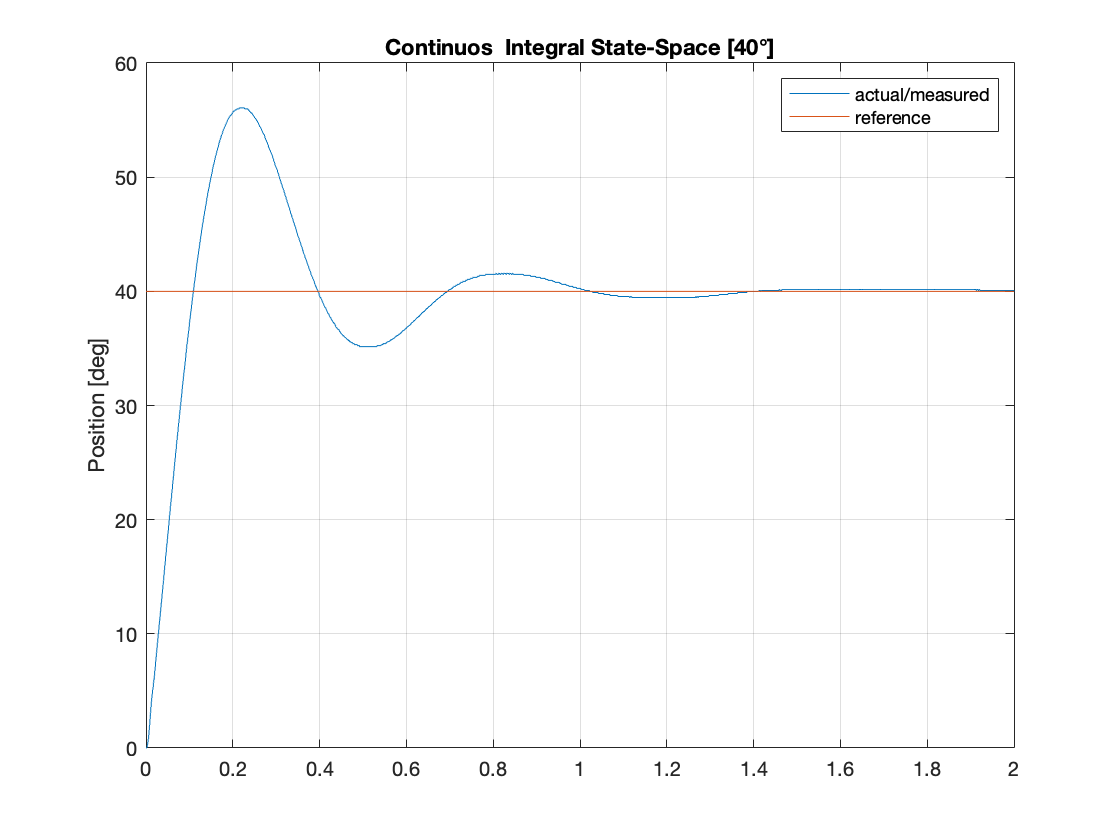

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','40');

% Controller
set_param('Cont_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Cont_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Cont_ReducedOrder/Controller/State feedback gain','Gain','robust.K','Multiplication','Matrix(K*u)');
set_param('Cont_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Cont_ReducedOrder/Controller/Ki','Gain','robust.Ki'); % Ki

% Continuos Reduced state observer
set_param('Cont_ReducedOrder/Reduced Order Observer','A','reduced.A0','B','reduced.B0','C','reduced.C0','D','reduced.D0');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Continuos  Integral State-Space [40°]');
legend('actual/measured', 'reference');

#### Simulation results [$$70°$$] 

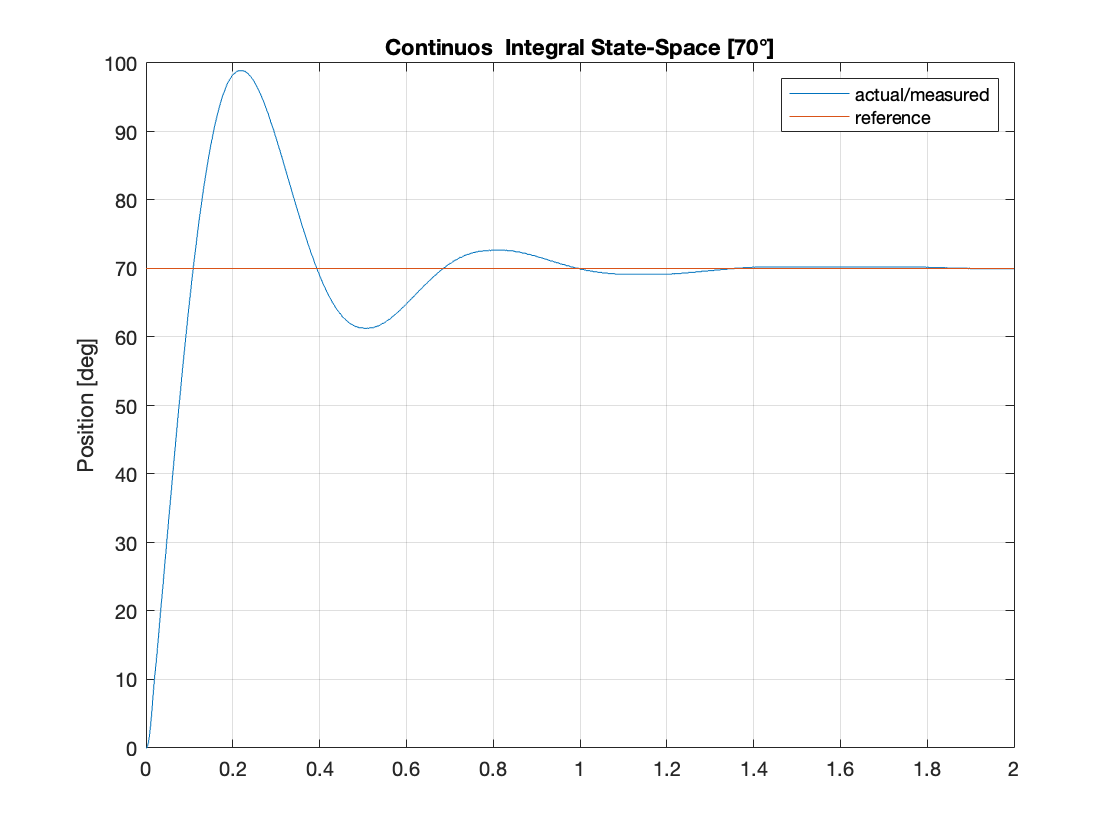

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','70');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Continuos  Integral State-Space [70°]');
legend('actual/measured', 'reference');

#### Simulation results [$$120°$$] 

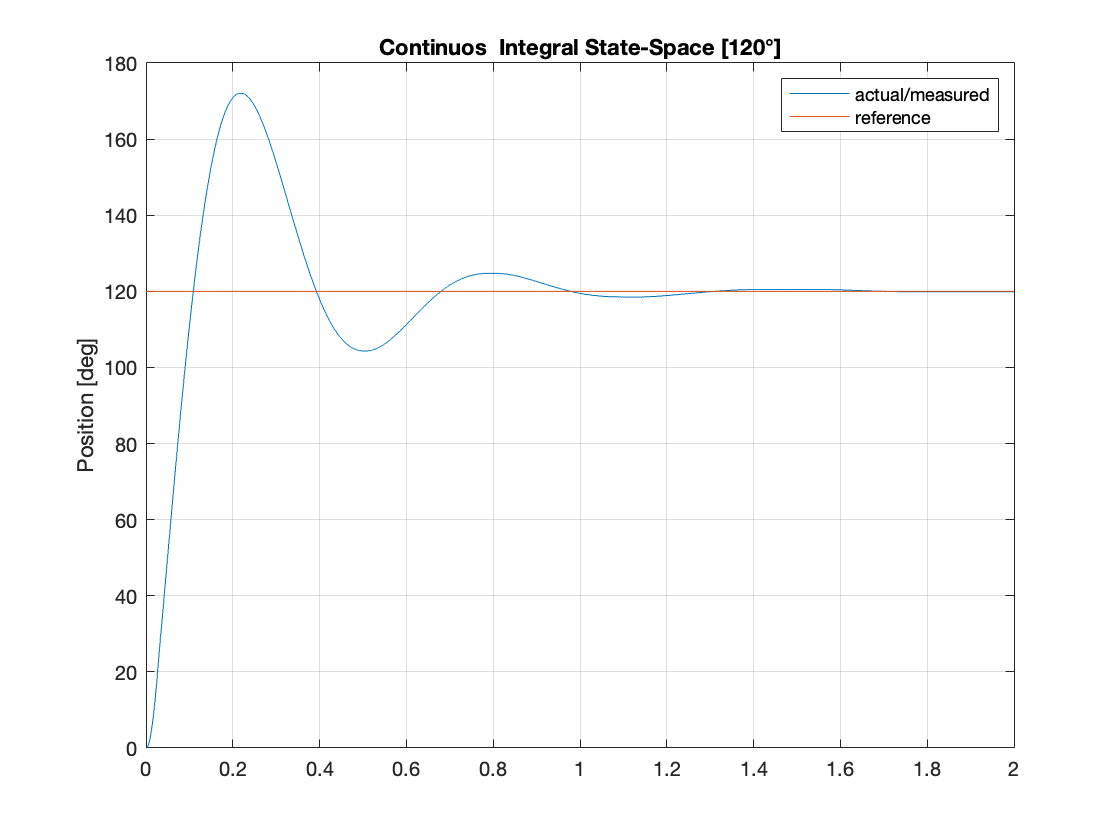

% Step
set_param('Cont_ReducedOrder/Step','Time','0','Before','0','After','120');

% Run simulation
sim('Cont_ReducedOrder');
 
% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Continuos  Integral State-Space [120°]');
legend('actual/measured', 'reference');

## Reduced-Order Observer [Discrete-case: Forward]

## 2.1.2.6-2.1.2.7 INTEGRAL

#### Simulation results [$$T_s = 1ms$$] 

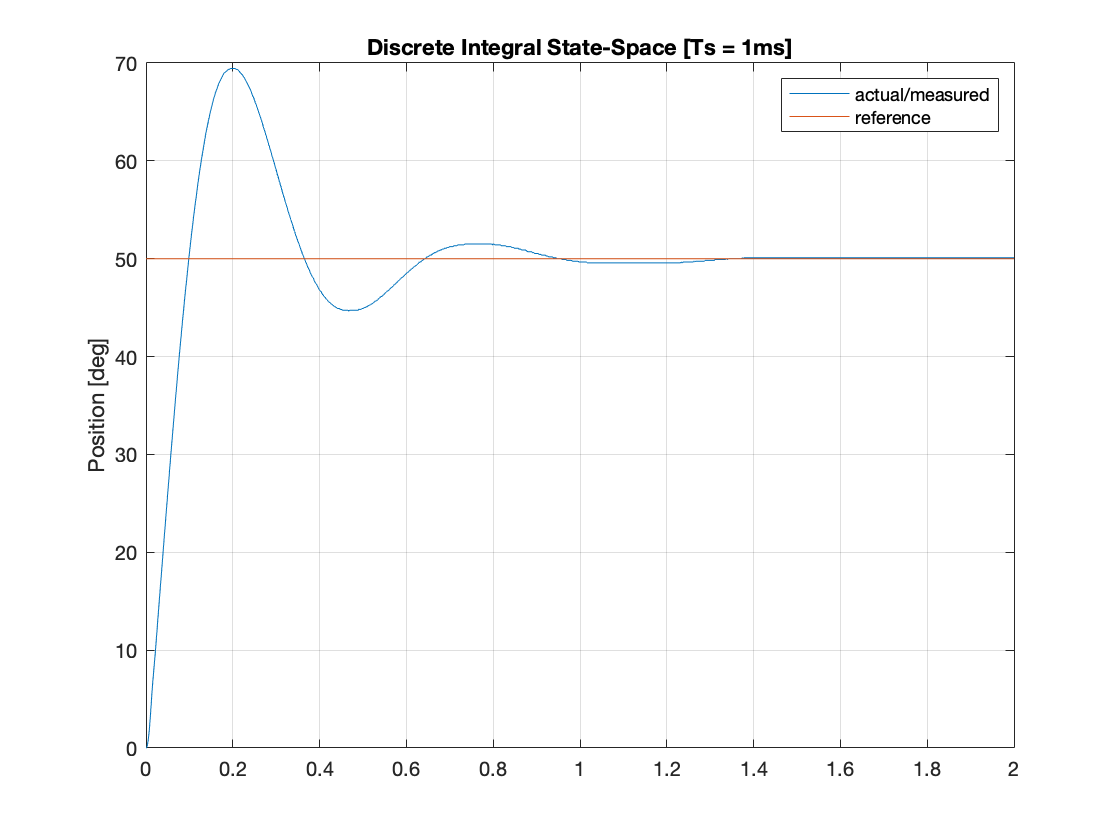

% Sampling time
T_samp = 0.001;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','robust.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','robust.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_7_1ms.t = simres.time; % time vector 
reduced_7_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_7_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_7_1ms.t, reduced_7_1ms.thl);
hold on;
plot(reduced_7_1ms.t, reduced_7_1ms.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 1ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$] 

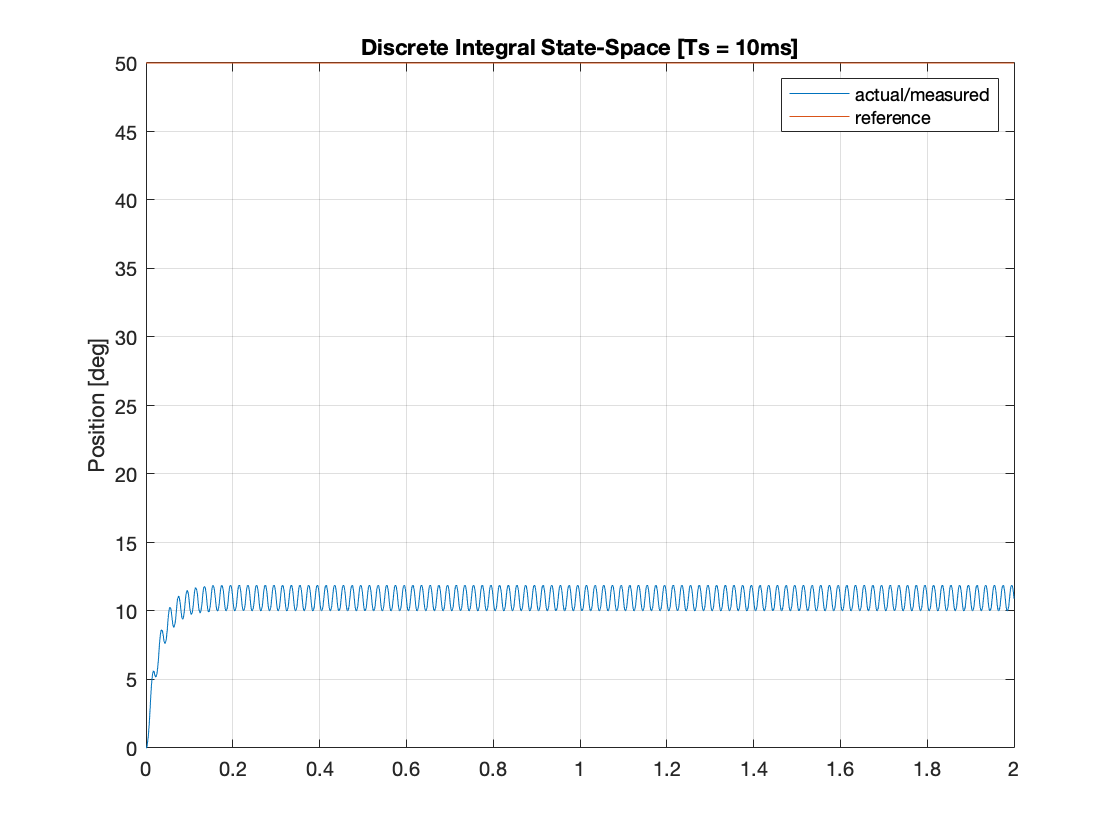

% Sampling time
T_samp = 0.01;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_7_10ms.t = simres.time; % time vector 
reduced_7_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_7_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_7_10ms.t, reduced_7_10ms.thl);
hold on;
plot(reduced_7_10ms.t, reduced_7_10ms.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 10ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$] 

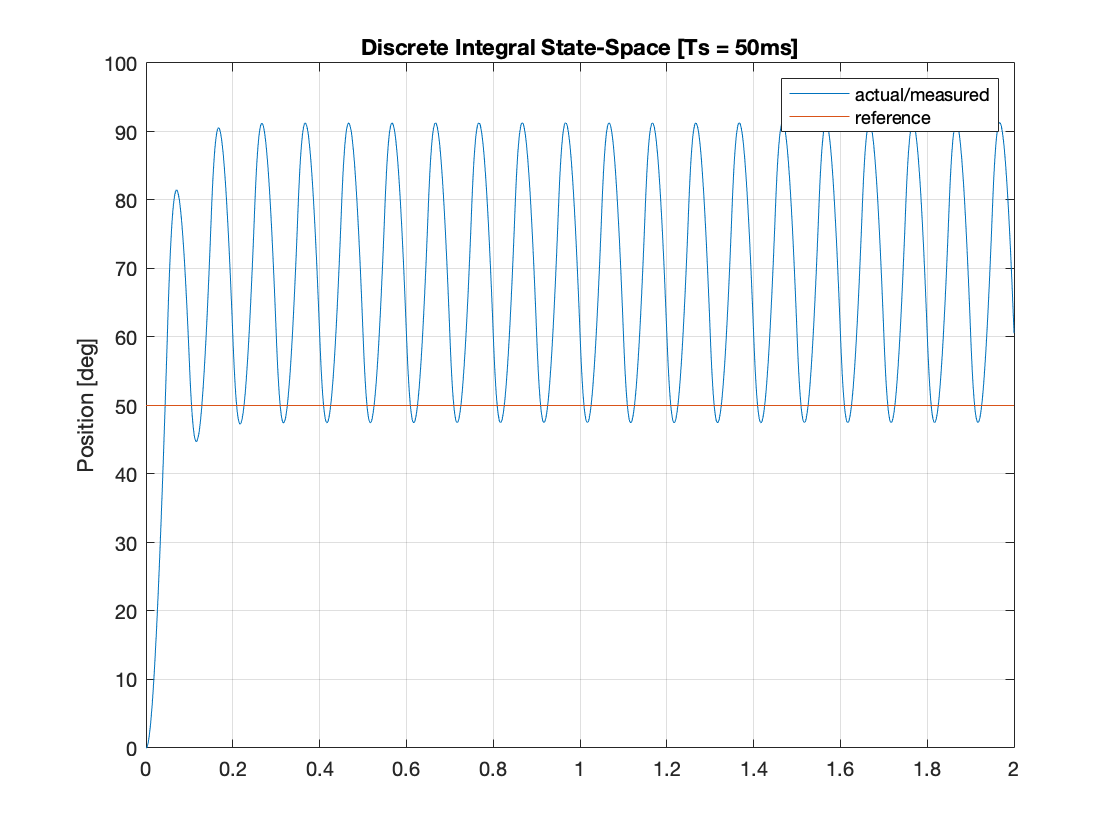

% Sampling time
T_samp = 0.05;

% PHY0
reduced.Phy0 = 1 + reduced.A0*T_samp;
% GAMMA0
reduced.Gamma0 = reduced.B0*T_samp;
% HO
reduced.H0 = reduced.C0;
% J0
reduced.J0 = reduced.D0;

set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced_7_50ms.t = simres.time; % time vector 
reduced_7_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_7_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_7_50ms.t, reduced_7_50ms.thl);
hold on;
plot(reduced_7_50ms.t, reduced_7_50ms.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 50ms]');
legend('actual/measured', 'reference');

## Reduced-Order Observer [Discrete-case: ZOH]

## 2.1.2.8 NOMINAL

#### Simulation results [$$T_s = 1ms$$] 

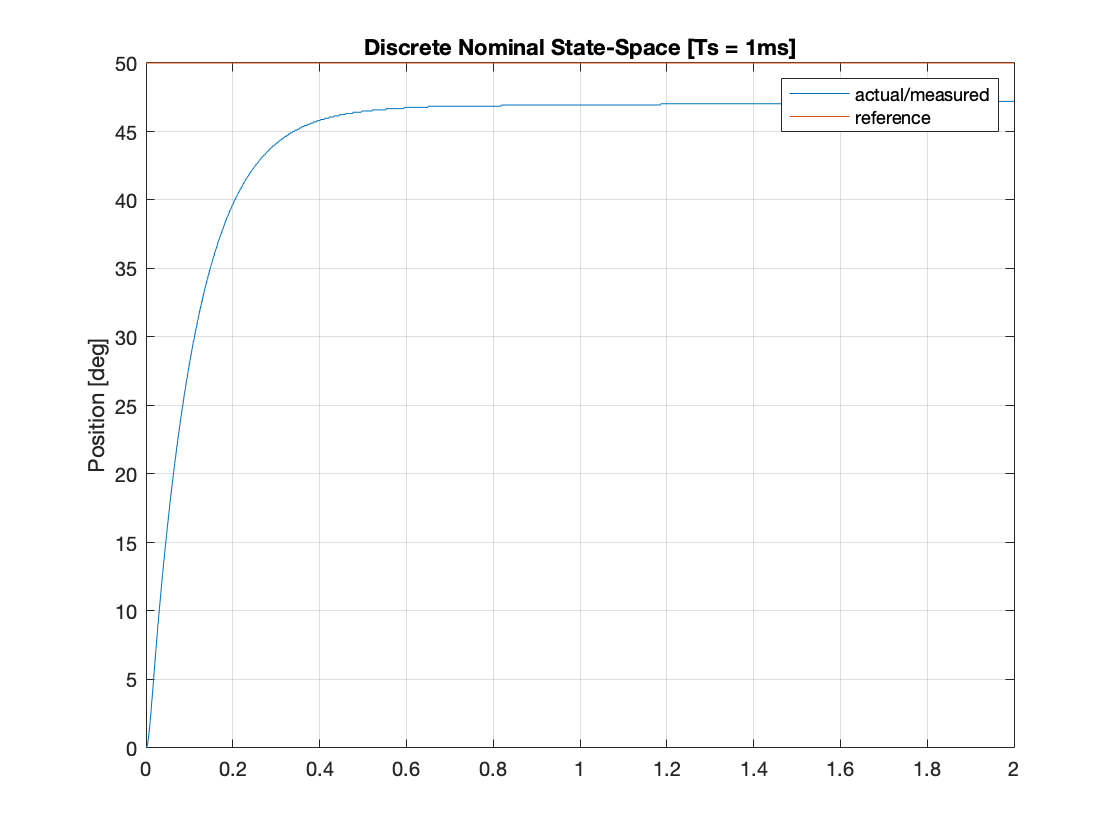

% Sampling time
T_samp = 0.001;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','nominal.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 1ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$] 

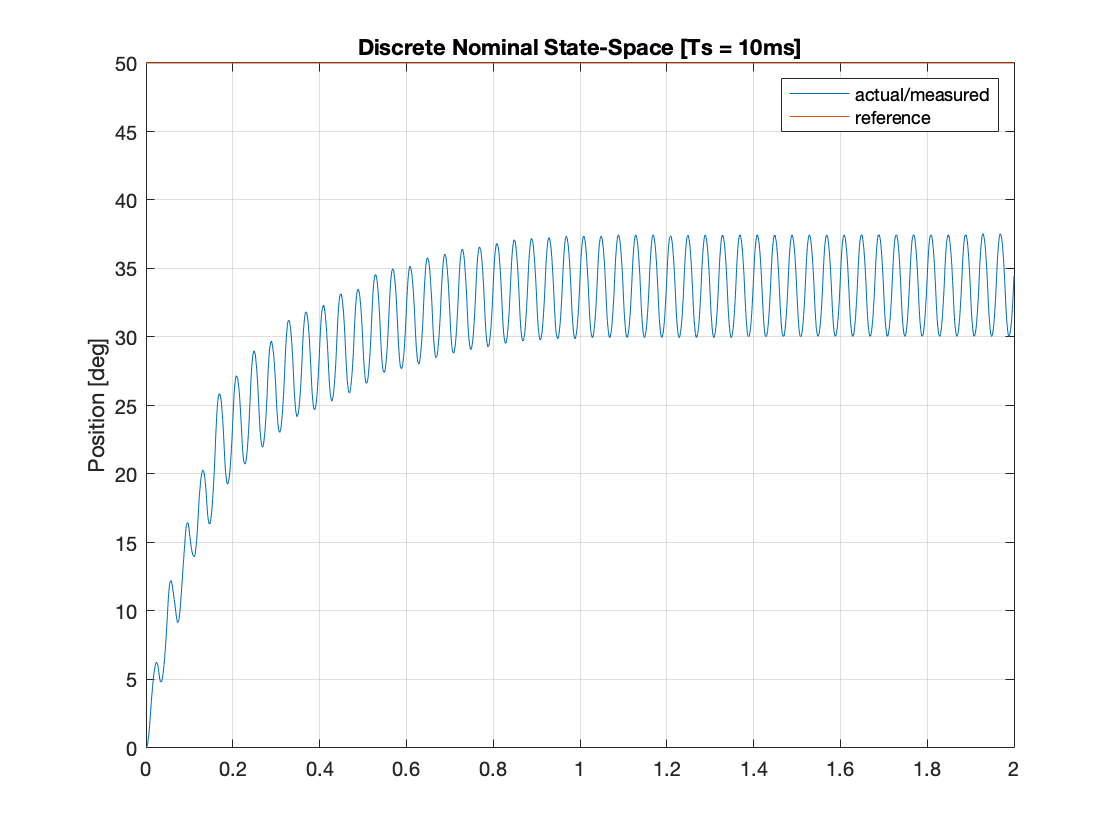

% Sampling time
T_samp = 0.01;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 10ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$] 

% Sampling time
T_samp = 0.05;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 50ms]');
legend('actual/measured', 'reference');

## Reduced-Order Observer [Discrete-case: ZOH]

## 2.1.2.8 INTEGRAL

#### Simulation results [$$T_s = 1ms$$] 

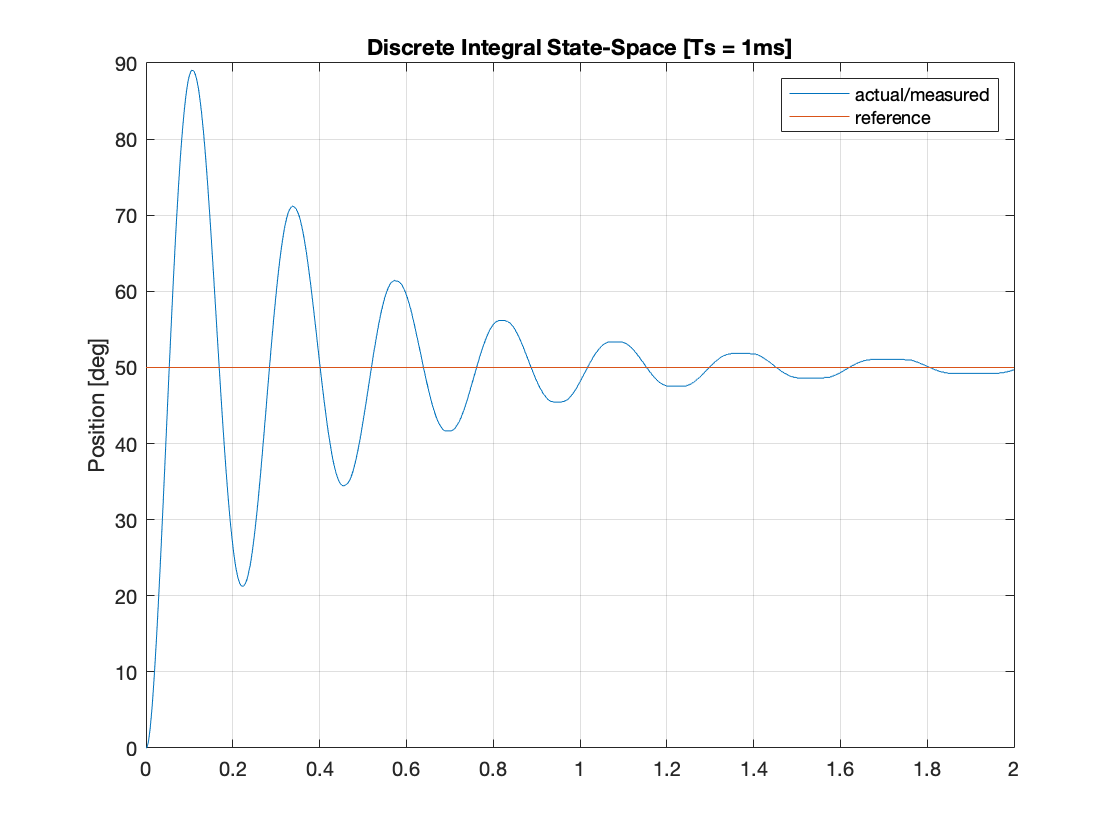

% Sampling time
T_samp = 0.001;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','nominal.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','nominal.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','nominal.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','robust.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 1ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 10ms$$] 

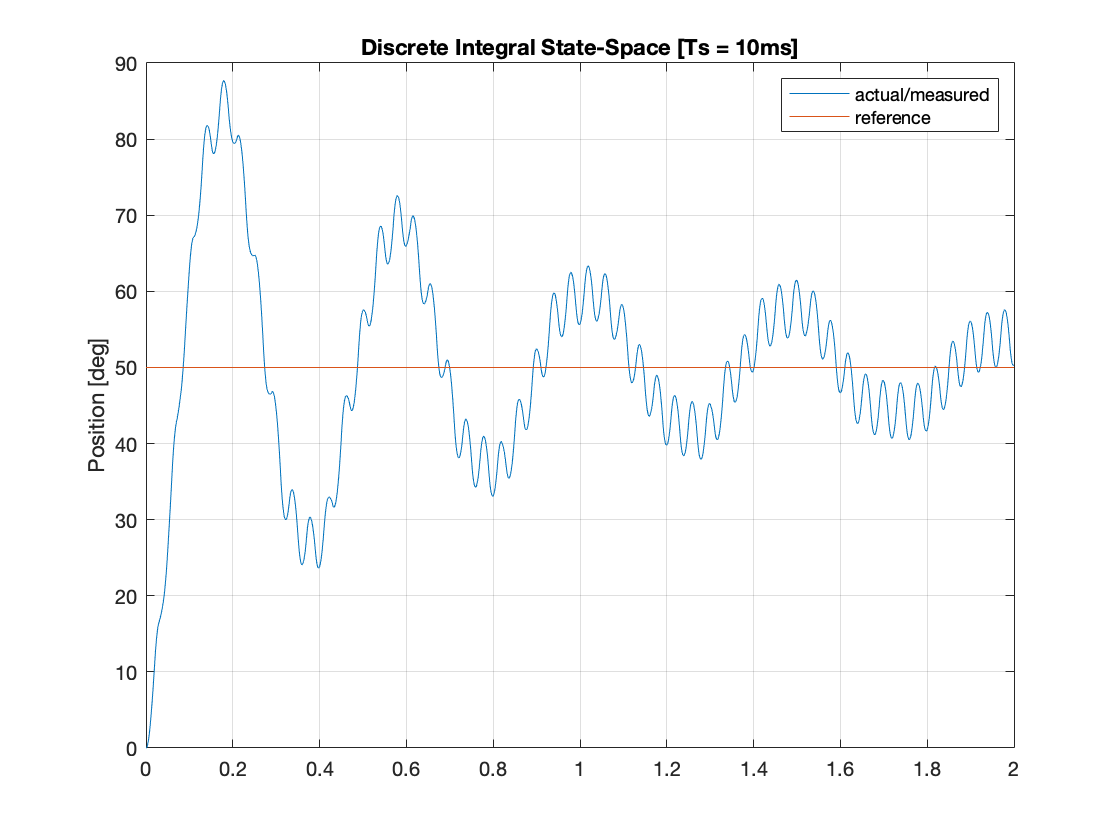

% Sampling time
T_samp = 0.01;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Controller
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 10ms]');
legend('actual/measured', 'reference');

#### Simulation results [$$T_s = 50ms$$] 

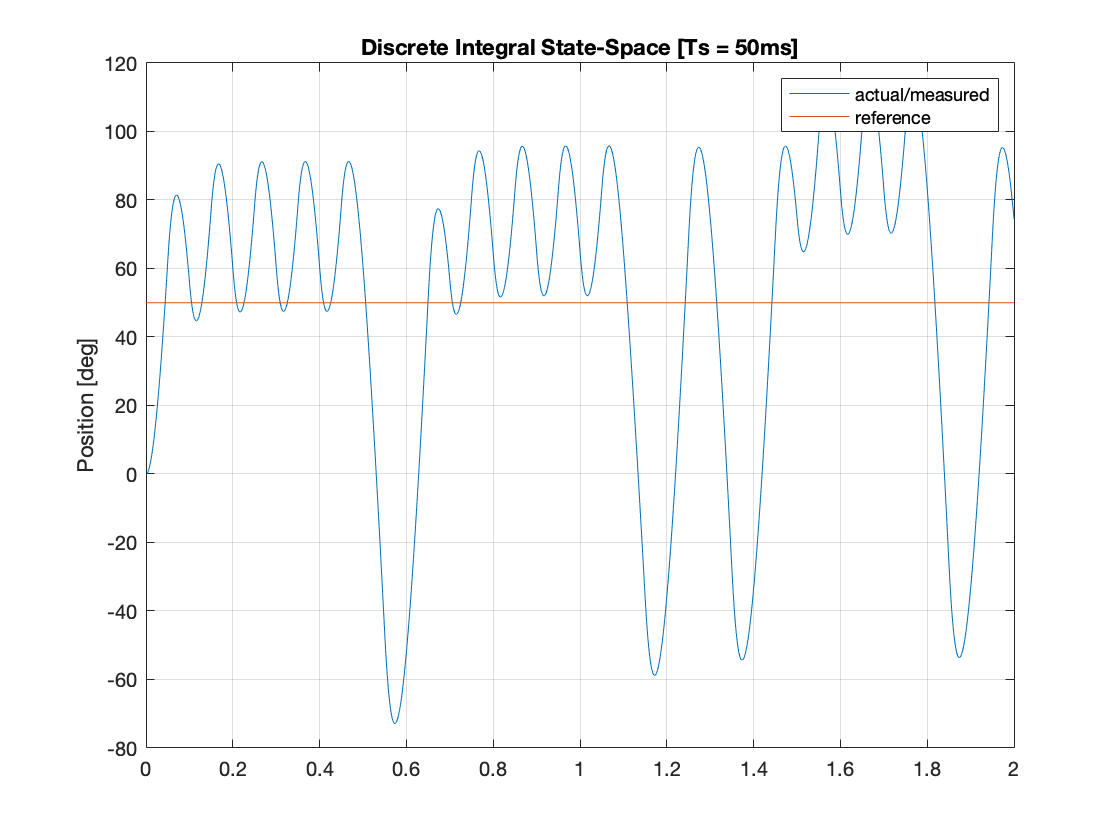

% Sampling time
T_samp = 0.05;

[reduced.Phy0,reduced.Gamma0,reduced.H0,reduced.J0] = ssdata(c2d(ss(reduced.A0,reduced.B0,reduced.C0,reduced.D0),T_samp,'zoh'));

% Controller
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Backward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','reduced.Phy0','B','reduced.Gamma0','C','reduced.H0','D','reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');

% Extract simulation results
reduced.t = simres.time; % time vector 
reduced.thl = simres.signals(1).values(:,1); % load position
reduced.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced.t, reduced.thl);
hold on;
plot(reduced.t, reduced.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 50ms]');
legend('actual/measured', 'reference');

# Direct digital design

## Reduced-Order Observer [Discrete]

## 2.2.1-2.2.2-2.2.3 NOMINAL

% Continuos state-Space model
state_space.T_m = (simp_model.Req*est_par.J_eq)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.K_m = (drv.dcgain*mot.Kt)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.A = [0 1;0 -1/state_space.T_m];
state_space.B = [0;state_space.K_m/(state_space.T_m*gbox.N)];
state_space.C = [1 0];
state_space.D = 0;

% Sampling time
T_samp = 0.001;

% Exact discretized state-space model
[state_space.Phy,state_space.Gamma,state_space.H,state_space.J] = ssdata(c2d(ss(state_space.A,state_space.B,state_space.C,state_space.D),T_samp,'zoh'));
state_space.Phy

ans =     1.0000    0.0010
         0    0.9757


% Continuos controller tf
s = tf('s');
Cs = pid.Kp + pid.Ki/s + pid.Kd*s/(pid.sim.T_l*s + 1);
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced.L = place(state_space.Phy(2,2),state_space.Phy(1,2),lambda_z);

% Phy0
digital_des_reduced.Phy0 = state_space.Phy(2,2) - digital_des_reduced.L*state_space.Phy(1,2);

% Gamma0
digital_des_reduced.Gamma0 = [state_space.Gamma(2,1)-digital_des_reduced.L*state_space.Gamma(1,1) (state_space.Phy(2,2)-digital_des_reduced.L*state_space.Phy(1,2))*digital_des_reduced.L+state_space.Phy(2,1)-digital_des_reduced.L*state_space.Phy(1,1)];

% H0
digital_des_reduced.H0 = [0;1];

% J0
digital_des_reduced.J0 = [0 1;0 digital_des_reduced.L];

% Nominal Nx Nu [DISCRETE]
digital_des_reduced.X = linsolve([state_space.Phy - eye(2),state_space.Gamma;state_space.H 0],[0;0;1]);
digital_des_reduced.N_x = digital_des_reduced.X(1:2,:);
digital_des_reduced.N_u = digital_des_reduced.X(3,:);

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
digital_des_reduced.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
digital_des_reduced.wn = 3/(digital_des_reduced.delta*ts);

% Pole placement [DISCRETE]
digital_des_reduced.p1_cont = -digital_des_reduced.delta*digital_des_reduced.wn + 1i*digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);
digital_des_reduced.p1_disc = exp(digital_des_reduced.p1_cont*T_samp);
digital_des_reduced.p2_cont = conj(digital_des_reduced.p1_cont);
digital_des_reduced.p2_disc = exp(digital_des_reduced.p2_cont*T_samp);
digital_des_reduced.poles_disc = [digital_des_reduced.p1_disc digital_des_reduced.p2_disc];

% K
digital_des_reduced.K = place(state_space.Phy,state_space.Gamma,digital_des_reduced.poles_disc);

#### Simulation results [$$T_s = 1ms$$] 

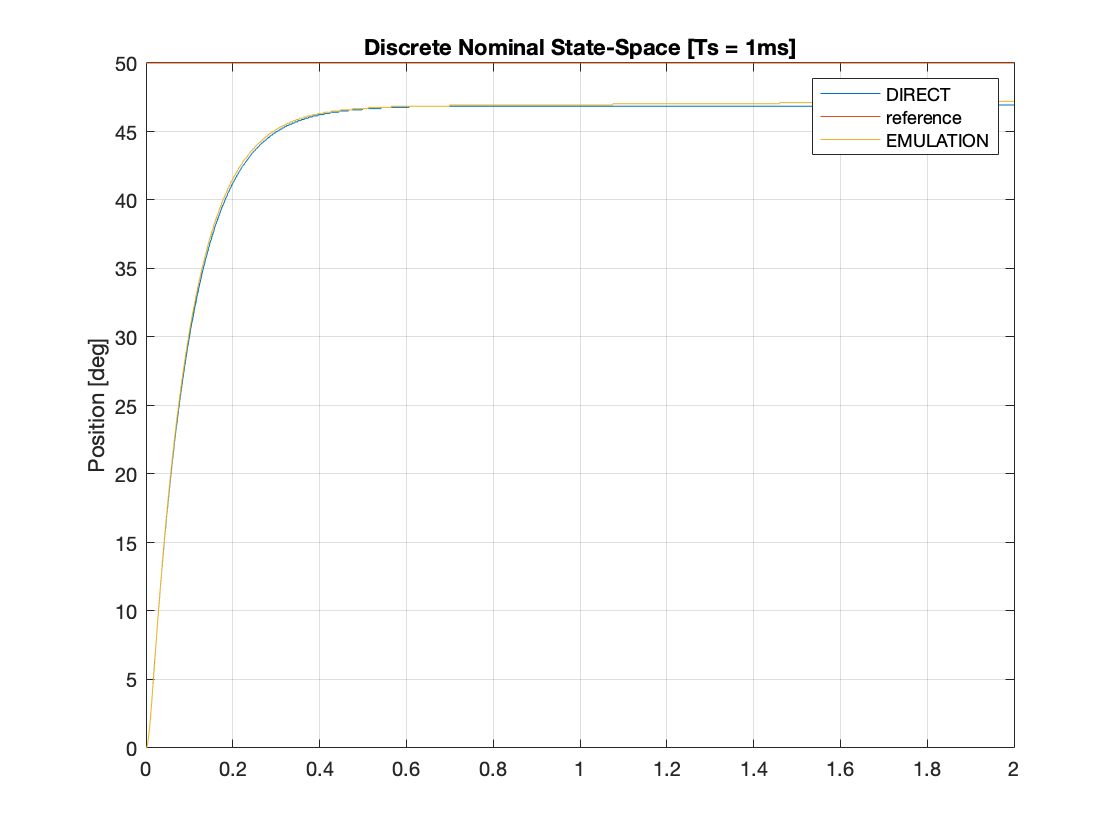

% Sampling time
T_samp = 0.001;

% Open Simulink model
open_system('Simulink/Disc_ReducedOrder.slx');
% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');
% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced.Phy0','B','digital_des_reduced.Gamma0','C','digital_des_reduced.H0','D','digital_des_reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_4_1ms.t = simres.time; % time vector 
reduced_4_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_4_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_4_1ms.t, reduced_4_1ms.thl);
hold on;
plot(reduced_4_1ms.t, reduced_4_1ms.thl_Ref);
hold on;
plot(reduced_3_1ms.t, reduced_3_1ms.thl);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 1ms]');
legend('DIRECT', 'reference', 'EMULATION');

#### Simulation results [$$T_s = 10ms$$] 

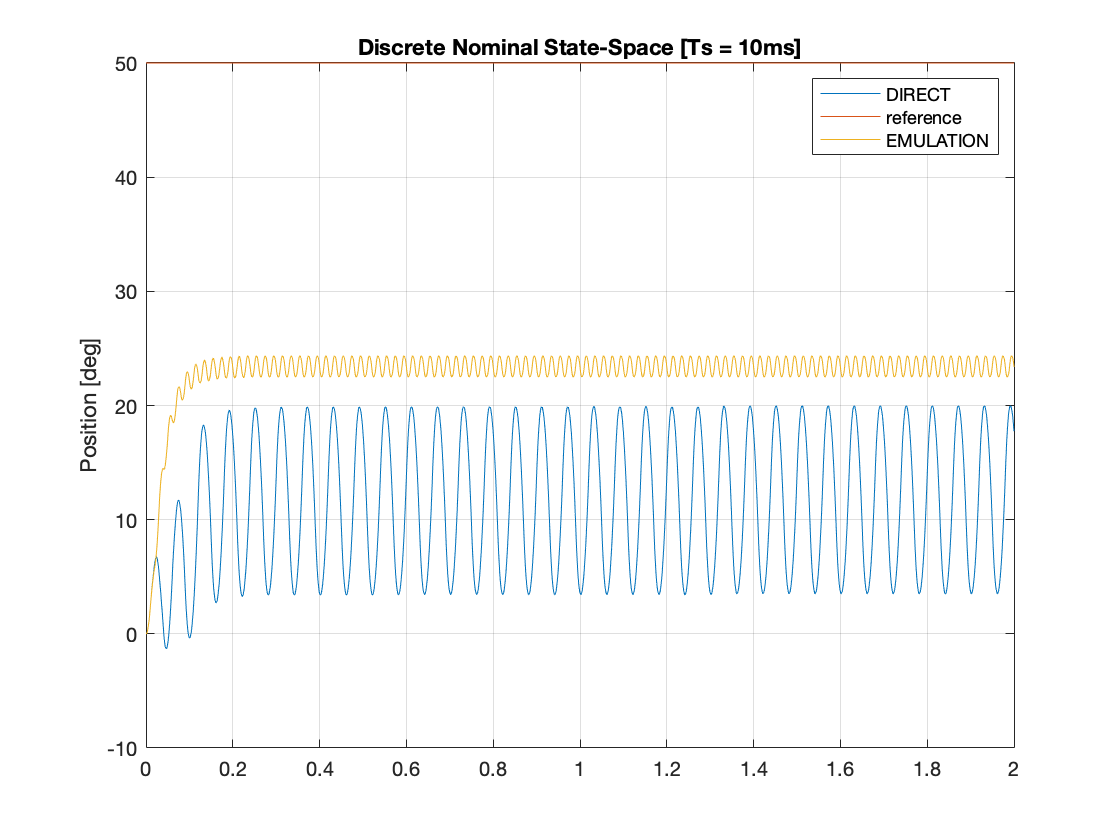

% Sampling time
T_samp = 0.01;

% Open Simulink model
open_system('Simulink/Disc_ReducedOrder.slx');
% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');
% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced.Phy0','B','digital_des_reduced.Gamma0','C','digital_des_reduced.H0','D','digital_des_reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_4_10ms.t = simres.time; % time vector 
reduced_4_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_4_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_4_10ms.t, reduced_4_10ms.thl);
hold on;
plot(reduced_4_10ms.t, reduced_4_10ms.thl_Ref);
hold on;
plot(reduced_3_10ms.t, reduced_3_10ms.thl);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 10ms]');
legend('DIRECT', 'reference', 'EMULATION');

#### Simulation results [$$T_s = 50ms$$] 

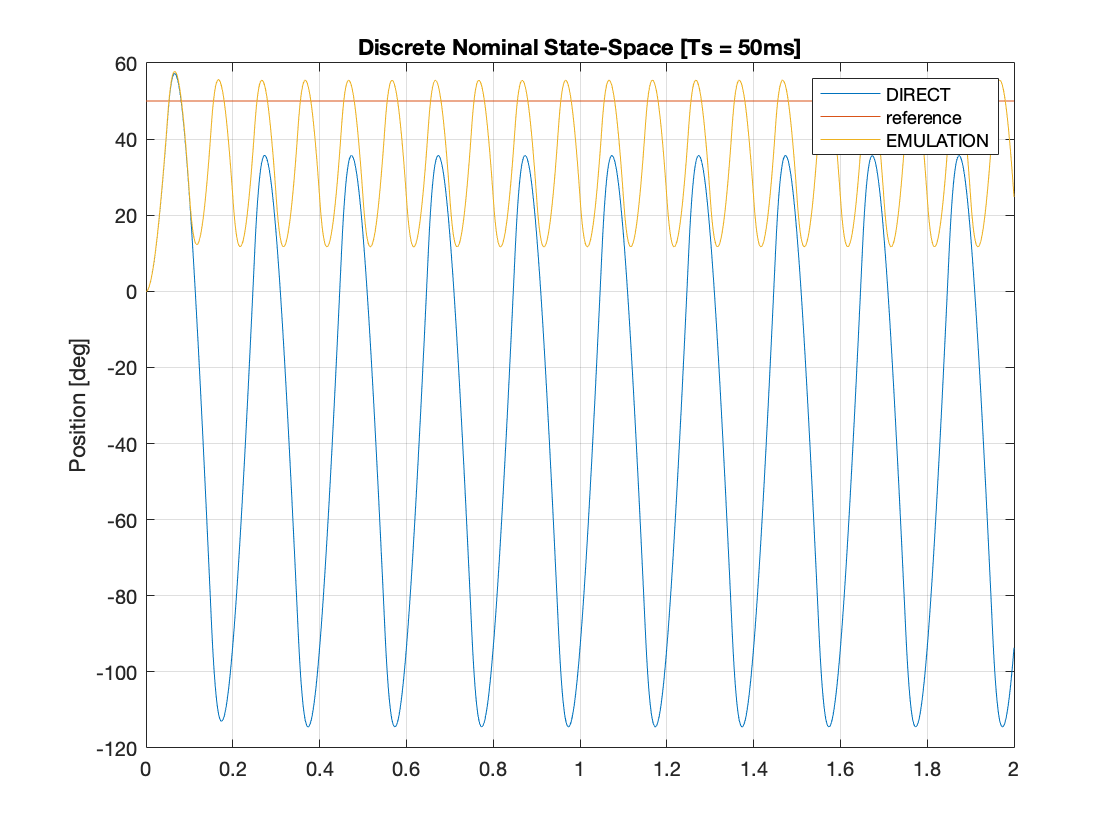

% Sampling time
T_samp = 0.05;

% Open Simulink model
open_system('Simulink/Disc_ReducedOrder.slx');
% Set parameters
set_param('Disc_ReducedOrder', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2', ...
    'AlgebraicLoopMsg','none');
% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','0'); % Nominal
set_param('Disc_ReducedOrder/Controller/Ki','Gain','0'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Integration: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced.Phy0','B','digital_des_reduced.Gamma0','C','digital_des_reduced.H0','D','digital_des_reduced.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_4_50ms.t = simres.time; % time vector 
reduced_4_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_4_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_4_50ms.t, reduced_4_50ms.thl);
hold on;
plot(reduced_4_50ms.t, reduced_4_50ms.thl_Ref);
hold on;
plot(reduced_3_50ms.t, reduced_3_50ms.thl);
ylabel('Position [deg]');
grid on;
title('Discrete Nominal State-Space [Ts = 50ms]');
legend('DIRECT', 'reference', 'EMULATION');

## Reduced-Order Observer [Discrete]

## 2.2.4 INTEGRAL

% Augmented state-space
digital_des_reduced_int.Phie = [1 state_space.H;[0;0] state_space.Phy];
digital_des_reduced_int.Gammae = [0;state_space.Gamma];
digital_des_reduced_int.He = [0 state_space.H];

% Real and imaginary parts of the eigenvalues
digital_des_reduced_int.sigma = -digital_des_reduced.delta*digital_des_reduced.wn;
digital_des_reduced_int.wd = digital_des_reduced.wn*sqrt(1-digital_des_reduced.delta^2);


#### Simulation results [$$T_s = 1ms$$] 

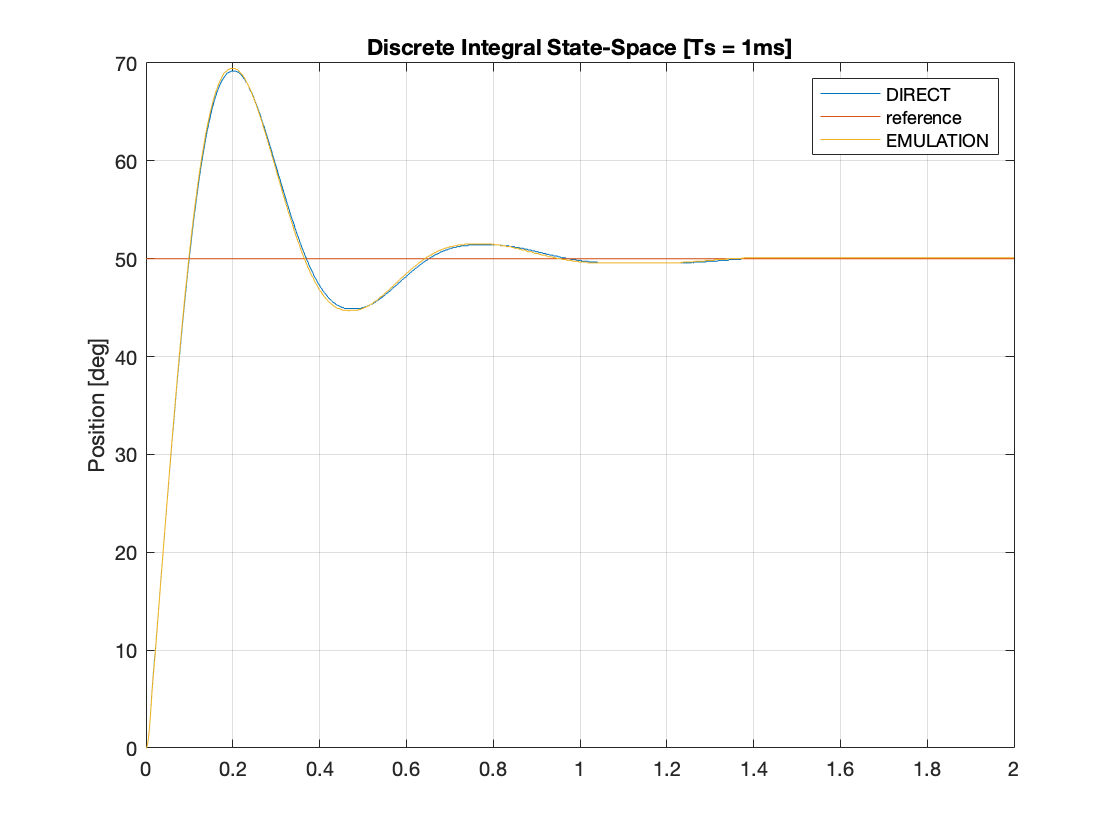

% Sampling time
T_samp = 0.001;

% Reduced order Observer eigenvalue
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced_int.L = place(state_space.Phy(2,2),state_space.Phy(1,2),lambda_z);

% Phy0
digital_des_reduced_int.Phy0 = state_space.Phy(2,2) - digital_des_reduced_int.L*state_space.Phy(1,2);

% Gamma0
digital_des_reduced_int.Gamma0 = [state_space.Gamma(2,1)-digital_des_reduced_int.L*state_space.Gamma(1,1) (state_space.Phy(2,2)-digital_des_reduced_int.L*state_space.Phy(1,2))*digital_des_reduced_int.L+state_space.Phy(2,1)-digital_des_reduced_int.L*state_space.Phy(1,1)];

% H0
digital_des_reduced_int.H0 = [0;1];

% J0
digital_des_reduced_int.J0 = [0 1;0 digital_des_reduced_int.L];

% Pole placement
digital_des_reduced_int.p1_cont = 2*digital_des_reduced_int.sigma + 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p1_disc = exp(digital_des_reduced_int.p1_cont*T_samp);
digital_des_reduced_int.p2_cont = 2*digital_des_reduced_int.sigma - 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p2_disc = exp(digital_des_reduced_int.p2_cont*T_samp);
digital_des_reduced_int.p3_cont = 2*digital_des_reduced_int.sigma;
digital_des_reduced_int.p3_disc = exp(digital_des_reduced_int.p3_cont*T_samp);

digital_des_reduced_int.poles_disc = [digital_des_reduced_int.p1_disc,digital_des_reduced_int.p2_disc,digital_des_reduced_int.p3_disc];

% Ke,Ki,K
digital_des_reduced_int.Ke = place(digital_des_reduced_int.Phie,digital_des_reduced_int.Gammae,digital_des_reduced_int.poles_disc);
digital_des_reduced_int.Ki = digital_des_reduced_int.Ke(1);
digital_des_reduced_int.K = digital_des_reduced_int.Ke(1,2:3);

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced_int.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','digital_des_reduced_int.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced_int.Phy0','B','digital_des_reduced_int.Gamma0','C','digital_des_reduced_int.H0','D','digital_des_reduced_int.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_5_1ms.t = simres.time; % time vector 
reduced_5_1ms.thl = simres.signals(1).values(:,1); % load position
reduced_5_1ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_5_1ms.t, reduced_5_1ms.thl);
hold on;
plot(reduced_5_1ms.t, reduced_5_1ms.thl_Ref);
hold on;
plot(reduced_7_1ms.t, reduced_7_1ms.thl);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 1ms]');
legend('DIRECT', 'reference', 'EMULATION');

#### Simulation results [$$T_s = 10ms$$] 

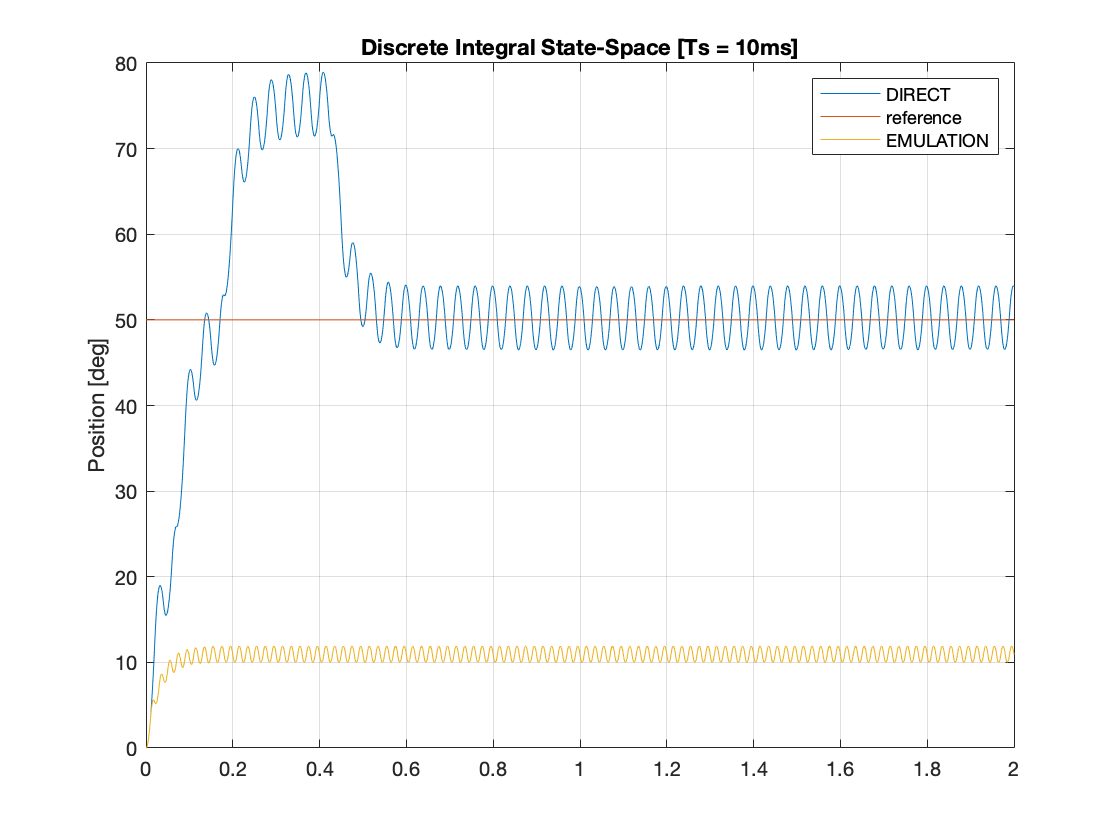

% Sampling time
T_samp = 0.01;

% Reduced order Observer eigenvalue
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced_int.L = place(state_space.Phy(2,2),state_space.Phy(1,2),lambda_z);

% Phy0
digital_des_reduced_int.Phy0 = state_space.Phy(2,2) - digital_des_reduced_int.L*state_space.Phy(1,2);

% Gamma0
digital_des_reduced_int.Gamma0 = [state_space.Gamma(2,1)-digital_des_reduced_int.L*state_space.Gamma(1,1) (state_space.Phy(2,2)-digital_des_reduced_int.L*state_space.Phy(1,2))*digital_des_reduced_int.L+state_space.Phy(2,1)-digital_des_reduced_int.L*state_space.Phy(1,1)];

% H0
digital_des_reduced_int.H0 = [0;1];

% J0
digital_des_reduced_int.J0 = [0 1;0 digital_des_reduced_int.L];

% Pole placement
digital_des_reduced_int.p1_cont = 2*digital_des_reduced_int.sigma + 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p1_disc = exp(digital_des_reduced_int.p1_cont*T_samp);
digital_des_reduced_int.p2_cont = 2*digital_des_reduced_int.sigma - 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p2_disc = exp(digital_des_reduced_int.p2_cont*T_samp);
digital_des_reduced_int.p3_cont = 2*digital_des_reduced_int.sigma;
digital_des_reduced_int.p3_disc = exp(digital_des_reduced_int.p3_cont*T_samp);

digital_des_reduced_int.poles_disc = [digital_des_reduced_int.p1_disc,digital_des_reduced_int.p2_disc,digital_des_reduced_int.p3_disc];

% Ke,Ki,K
digital_des_reduced_int.Ke = place(digital_des_reduced_int.Phie,digital_des_reduced_int.Gammae,digital_des_reduced_int.poles_disc);
digital_des_reduced_int.Ki = digital_des_reduced_int.Ke(1);
digital_des_reduced_int.K = digital_des_reduced_int.Ke(1,2:3);

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced_int.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','digital_des_reduced_int.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced_int.Phy0','B','digital_des_reduced_int.Gamma0','C','digital_des_reduced_int.H0','D','digital_des_reduced_int.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_5_10ms.t = simres.time; % time vector 
reduced_5_10ms.thl = simres.signals(1).values(:,1); % load position
reduced_5_10ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_5_10ms.t, reduced_5_10ms.thl);
hold on;
plot(reduced_5_10ms.t, reduced_5_10ms.thl_Ref);
hold on;
plot(reduced_7_10ms.t, reduced_7_10ms.thl);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 10ms]');
legend('DIRECT', 'reference', 'EMULATION');

#### Simulation results [$$T_s = 50ms$$] 

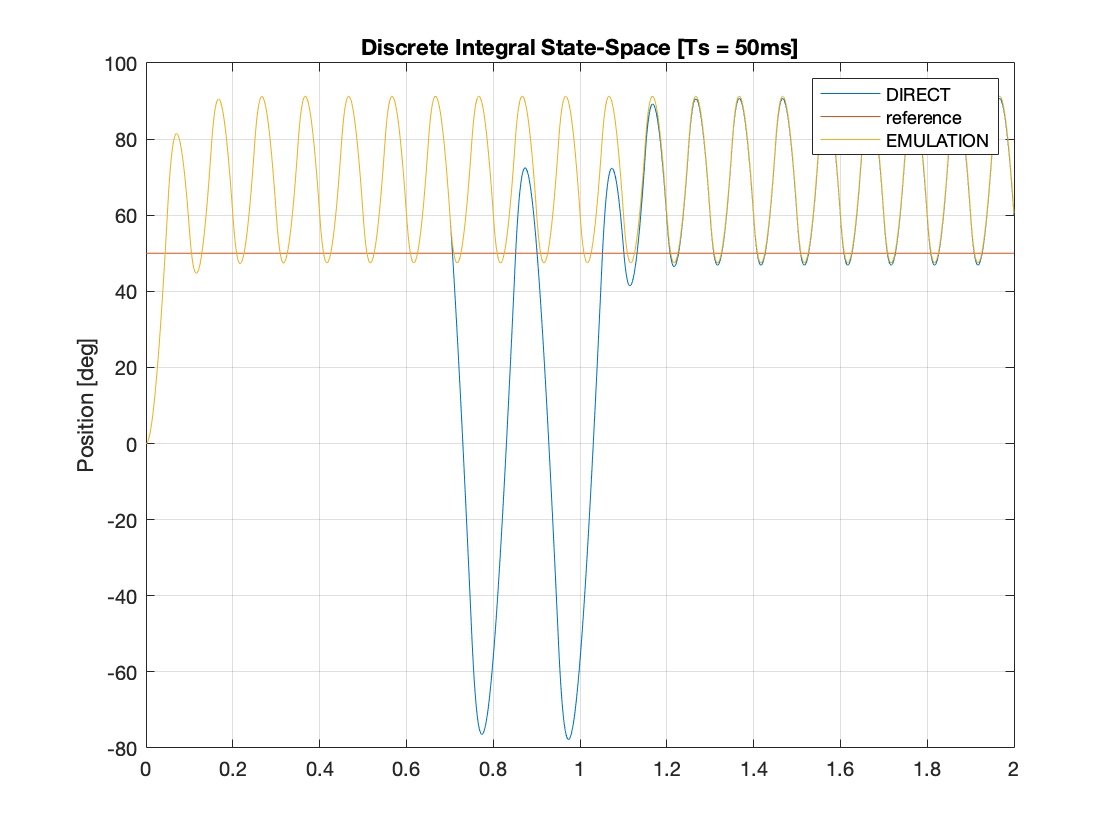

% Sampling time
T_samp = 0.05;

% Reduced order Observer eigenvalue
lambda_z = exp(5*min(eig(Cs))*T_samp);

% Compute L
digital_des_reduced_int.L = place(state_space.Phy(2,2),state_space.Phy(1,2),lambda_z);

% Phy0
digital_des_reduced_int.Phy0 = state_space.Phy(2,2) - digital_des_reduced_int.L*state_space.Phy(1,2);

% Gamma0
digital_des_reduced_int.Gamma0 = [state_space.Gamma(2,1)-digital_des_reduced_int.L*state_space.Gamma(1,1) (state_space.Phy(2,2)-digital_des_reduced_int.L*state_space.Phy(1,2))*digital_des_reduced_int.L+state_space.Phy(2,1)-digital_des_reduced_int.L*state_space.Phy(1,1)];

% H0
digital_des_reduced_int.H0 = [0;1];

% J0
digital_des_reduced_int.J0 = [0 1;0 digital_des_reduced_int.L];

% Pole placement
digital_des_reduced_int.p1_cont = 2*digital_des_reduced_int.sigma + 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p1_disc = exp(digital_des_reduced_int.p1_cont*T_samp);
digital_des_reduced_int.p2_cont = 2*digital_des_reduced_int.sigma - 1i*digital_des_reduced_int.wd;
digital_des_reduced_int.p2_disc = exp(digital_des_reduced_int.p2_cont*T_samp);
digital_des_reduced_int.p3_cont = 2*digital_des_reduced_int.sigma;
digital_des_reduced_int.p3_disc = exp(digital_des_reduced_int.p3_cont*T_samp);

digital_des_reduced_int.poles_disc = [digital_des_reduced_int.p1_disc,digital_des_reduced_int.p2_disc,digital_des_reduced_int.p3_disc];

% Ke,Ki,K
digital_des_reduced_int.Ke = place(digital_des_reduced_int.Phie,digital_des_reduced_int.Gammae,digital_des_reduced_int.poles_disc);
digital_des_reduced_int.Ki = digital_des_reduced_int.Ke(1);
digital_des_reduced_int.K = digital_des_reduced_int.Ke(1,2:3);

% Step
set_param('Disc_ReducedOrder/Step','Time','0','Before','0','After','50');

% Controller DIRECT
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced_int.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','digital_des_reduced_int.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced_int.Phy0','B','digital_des_reduced_int.Gamma0','C','digital_des_reduced_int.H0','D','digital_des_reduced_int.J0','SampleTime','T_samp');

% Controller EMULATION
set_param('Disc_ReducedOrder/Controller/State feed-forward gain','Gain','digital_des_reduced.N_x');
set_param('Disc_ReducedOrder/Controller/Input feed-forward gain','Gain','digital_des_reduced.N_u');
set_param('Disc_ReducedOrder/Controller/State feedback gain','Gain','digital_des_reduced_int.K','Multiplication','Matrix(K*u)');
set_param('Disc_ReducedOrder/Enable Integral','Value','1'); % Integral
set_param('Disc_ReducedOrder/Controller/Ki','Gain','digital_des_reduced_int.Ki'); % Ki
set_param('Disc_ReducedOrder/Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler','SampleTime','T_samp'); % Integrator

% Discrete Reduced state observer
set_param('Disc_ReducedOrder/Discrete Reduced Order Observer','A','digital_des_reduced_int.Phy0','B','digital_des_reduced_int.Gamma0','C','digital_des_reduced_int.H0','D','digital_des_reduced_int.J0','SampleTime','T_samp');

% Run simulation
sim('Disc_ReducedOrder');
 
% Extract simulation results
reduced_5_50ms.t = simres.time; % time vector 
reduced_5_50ms.thl = simres.signals(1).values(:,1); % load position
reduced_5_50ms.thl_Ref = simres.signals(1).values(:,2); % load position reference

% Plot simulation results
figure
plot(reduced_5_50ms.t, reduced_5_50ms.thl);
hold on;
plot(reduced_5_50ms.t, reduced_5_50ms.thl_Ref);
hold on;
plot(reduced_7_50ms.t, reduced_7_50ms.thl);
ylabel('Position [deg]');
grid on;
title('Discrete Integral State-Space [Ts = 50ms]');
legend('DIRECT', 'reference', 'EMULATION');

% Sampling time
T_samp = 0.01;

ans = -2.3832

ans = 	1.0e+03 *

    0.0013   -1.0613


ans =      0
     1


ans =          0    1.0000
         0  313.6853
